# Paint4Net: visualisation toolbox for COBRA

## Author(s):

Andrejs Kostromins, Biosystems Group, Department of Computer Systems, Latvia University of Agriculture, Liela iela 2, LV-3001 Jelgava, Latvia. 

Egils Stalidzans, Institute of Microbiology and Biotechnology, University of Latvia, Jelgavas iela 1, LV-1004, Latvia.

## Reviewer(s): 

Agris Pentjuss, Institute of Microbiology and Biotechnology, University of Latvia, Jelgavas iela 1, LV-1004, Latvia.

## IMPORTANT NOTE

Paint4Net uses Bioinformatics Toolbox to generate visualisation layout, however it is not supported in .mlx causing an error during function execution. Thus the functions involving visualisation were run in regular MATLAB command window and each visualisation  layout was saved as a static figure and flaced in the .mlx tutorial, while the corresponding functions were run in .mlx with visualisation feature turned off (input argument *drawMap *was set to 'false') to get outputs (without visualisation) in .mlx without crashing. Be aware of this issue when you are running the functions in .mlx. All *drawMap *input arguments are set to 'true' in .mlx. Change it to 'false' to avoid an error. 

## INTRODUCTION

A visual analysis of reconstructions and large stoichiometric models with elastic change of the visualization scope and representation methods becomes increasingly important due to the rapidly growing size and number of available reconstructions.

The Paint4Net is a COBRA Toolbox extension for automatic generation of a hypergraph layout of defined scope with the steady state rates of reaction fluxes of stoichiometric models. Directionalities and fluxes of reactions are constantly represented in the visualization while detailed information about reaction (ID, name and synonyms, and formula) and metabolite (ID, name and synonyms, and charged formula) appears placing the cursor on the item of interest. Additionally Paint4Net functionality can be used to: (1) get lists of involved metabolites and dead end metabolites of the visualized part of the network, (2) exclude (filter) particular metabolites from representation, (3) find isolated parts of a network and (4) find running cycles when all the substrates are cut down. Layout pictures can be saved in various formats and easily distributed. 

**Two functions with their arguments are used in the Paint4Net to define the scope of visualization: (1) [involvedMets, deadEnds] = draw by rxn(model, rxns, drawMap, direction, initialMet, excludeMets, flux) – to define scope by a list of reactions and (2) [directionRxns, involvedMets, deadEnds] = draw by met(model, metAbbr, drawMap, radius, direction, excludeMets, flux) – to define the metabolite of interest to see linked reactions within radius of, for instance, 2 reactions.** The function draw_by_rxn has 7 input arguments: (1) model – stands for stoichiometric reconstruction or model with constraints, (2) rxns – stands for a list of the reactions of interest for analysis, (3) drawMap (optional) – stands for request to generate visualization ('true' or 'false', default is 'false'), (4) direction (optional) – stands for algorithm visualization mode ('struc', 'sub', 'prod' or 'both') in order to visualize structure (struc) of reconstructions without FBA data or visualize substrates (sub), products (prod) or substrates and products (both) for models with flux constraints and FBA data (default is 'struc'), (5) initialMet (optional) – stands for metabolite of interest to be used by function draw by met (default is empty), (6) excludeMets (optional) – stands for a list of the excludable metabolites as a filter and (7) flux (optional) – stands for vector of FBA data of reactions flux distribution (default is vector of x characters if flux is not calculated). The last 5 arguments are optional and can be unset. The function draw_by_rxn has 2 outputs: (1) involvedMets – stands for a list of involved metabolites depending on the input arguments and (2) deadEnds – stands for a list of dead-end metabolites depending on the input arguments. The function draw_by_met has 7 input arguments: (1) model – stands for stoichiometric reconstruction or model with constraints, (2) metAbbr – stands for an input for metabolite of interest for analysis, (3) drawMap (optional) – stands for request to generate visualization ('true' or 'false', default is 'false'), (4) radius (optional) – stands for distance indicator between metabolite of interest and involved reactions (default is 1), (5) direction (optional) – stands for algorithm visualization mode ('struc', 'sub', 'prod' or 'both') in order to visualize structure (struc) of reconstructions without FBA data or visualize substrates (sub), products (prod) or substrates and products (both) for models with flux constraints and FBA data (default is 'struc'), (6) excludeMets (optional) – stands for a list of the excludable metabolites as a filter and (7) flux (optional) – stands for vector of FBA data of reactions flux distribution (default is vector of x characters for no flux). The last 5 arguments are optional and can be unset. The function draw_by_met has 3 outputs: (1) directionRxns – stands for a list of involved reactions depending on the input arguments, (2) involvedMets – stands for a list of involved metabolites depending on the input arguments and (3) deadEnds – stands for alist of dead-end metabolites depending on the input arguments. 

The layout of the network is generated by Bioinformatics Toolbox using hierarchical (default), radial or equilibrium layout engine algorithm, which can be changed in the menu item “Tool” of the layout. The automatically generated layout stays the same as long as the scope of representation and directionality of reactions remain unchanged. The layout of automatically generated network can be changed by dragging metabolites or reactions for analysis or publishing needs. Still the new layout cannot be saved for next visualizations. The visual representation of information in the layout (see Fig. 1) allows quick assessment of running processes generally.

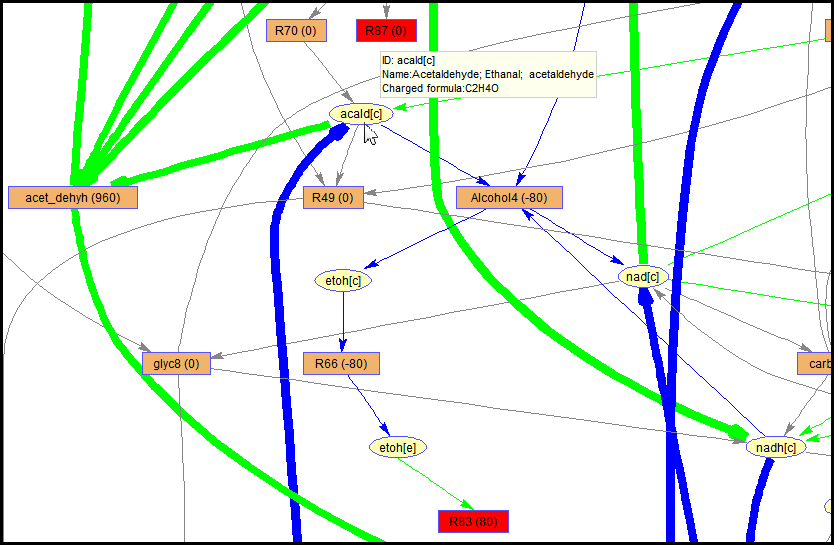

**Fig. 1 **Zoomed fragment of a large model. Reaction nodes (rectangle) contain IDs and flux rates. Metabolite nodes (ellipse) are marked by IDs. Forward and reverse fluxes (arrows) are green and blue correspondingly, zero fluxes are grey. The thickness of an arrow is proportional to the rate of flux. Rectangles of blocked and exchange reactions are marked by red. One node at a time can be chosen by a cursor to see detailed information: (1) ID, name, synonyms and equation for a reaction and (2) ID, name, synonyms and charged formula for a metabolite.  Metabolite *acald[c]*is selected by cursor for displaying of detailed information.  Creation of this figure is described in the “Anticipated results” section, Step 8.

Detailed information about any reaction and metabolite can be requested right on the visualization choosing the node of interest by cursor. To facilitate the analysis the Paint4Net creates a list of involved metabolites and a list of the dead end metabolites (metabolite cannot be produced or consumed caused by gap – missing reaction – in the model) (Thiele and Palsson, 2010) in the visualized part of the reaction network. That is a convenient feature analyzing larger visualizations where it becomes hard to be sure that a particular metabolite is or is not involved just by search of the abbreviation in the picture. The dead end metabolites are detected according to the S matrix (Palsson, 2006) of the biochemical model and the rates of reactions at steady state according to FBA. Flux rates below 10E−9 mmol g−1 h−1 are considered to be zero flux rates. To reduce the density of visualization a metabolite filter can be used. Stoichiometric model may have some particular metabolites (H, H2O, ATP, ADP, NAD, NADPH, NADP etc.), which are more involved in the metabolism, than other ones. It leads to a very tight interconnectivity and makes it harder to visualize larger models. For this reason both functions of the Paint4Net have special argument for the list of excludable metabolites. Each excluded metabolite reduces the number of interconnecting curves in the visualization of the model. Debugging of a model can be facilitated in several ways. The visualization shows the interconnections between reactions and metabolites and isolated parts of a network appear very clearly. There are three reasons why isolated reactions can be present in the model: (1) human made mistakes in the model while generating the model, (2) intentionally left gaps in case of no interest in specific metabolic process or (3) knowledge gaps in case of missing biochemical knowledge for the organism. Isolated parts can be related to metabolic dead-ends in the model (Thiele and Palsson, 2010). The Paint4Net is able to find the dead end metabolites and represent them in the visualization (red ellipses). Blocked reactions which cannot carry the fluxes (Thiele and Palsson, 2010) can appear in the model as intentionally blocked reactions (gene knockouts, flux constraints set to 0), however often there are cases when the model is stoichiometrically unbalanced or lower and upper bounds are set incorrectly. The Paint4Net can deal with this problem as well by showing the nodes of the blocked reactions in the visualization by red rectangles. The true power of visualization reflects when the user has to find Type III-extreme pathways (Thiele and Palsson, 2010) in the model. Those are stoichiometrically balanced cycles which can have fluxes even when all the substrate sources are cut down. According to FBA data the Paint4Net visualizes the network and then it is relatively easy to distinguish cycles by nonzero fluxes marked by green and blue arrows, which in most cases are caused by insufficient constraints of the flux and/or directionality. 

Paint4Net has been used in the development of stoichiometric models of Zymomonas mobilis (Pentjuss et al., 2013), Methanococcus maripaludis (Richards et al., 2016) and Kluyveromyces marxianus (Pentjuss et al., 2017). Paint4Net was used for to develop draft model, to identify network reactions connecting missing outputs to inputs and/or to produce figures for the published manuscript (Aurich and Thiele, 2012), (Demidenko et al., 2017), (Contador et al., 2015). It is used also for analysis and published figures in other studies (Koussa et al., 2014). Paint4Net is mentioned also as valuable supplement to other COBRA Tollboxes like ORCA (Mao and Verwoerd, 2014). Paint4Net has been used also for analysis of networks during building of modeling software (Rove et al., 2012) and supporting software tools (Rubina and Stalidzans, 2013), (Meitalovs and Stalidzans, 2013). Paint4Net is also used in a number of doctoral theses in different countries.

## MATERIALS

No materials are needed as Paint4Net is a software product.

## EQUIPMENT

The equipment has to be able to run MATLAB. 

## EQUIPMENT SETUP

The COBRA toolbox and the Bioinformatics toolbox are required to use the Paint4Net.

## PROCEDURE

The Paint4Net v1.3 contains two main commands for the visualization purposes:

- *[involvedMets, deadEnds] = draw_by_rxn(model, rxns, drawMap, direction, initialMet, excludeMets, flux)*;

- *[directionRxns, involvedMets, deadEnds] = draw_by_met(model,** metAbbr**, drawMap, radius, direction, excludeMets, flux)*.

## *Application of command* ***draw_by_rxn ***

***draw_by_rxn ***can be performed using **option** **A** in case COBRA model optimization results have to be visualized or **option** **B** if the interconnections between metabolites in COBRA file have to be visualized (See Fig. 2).

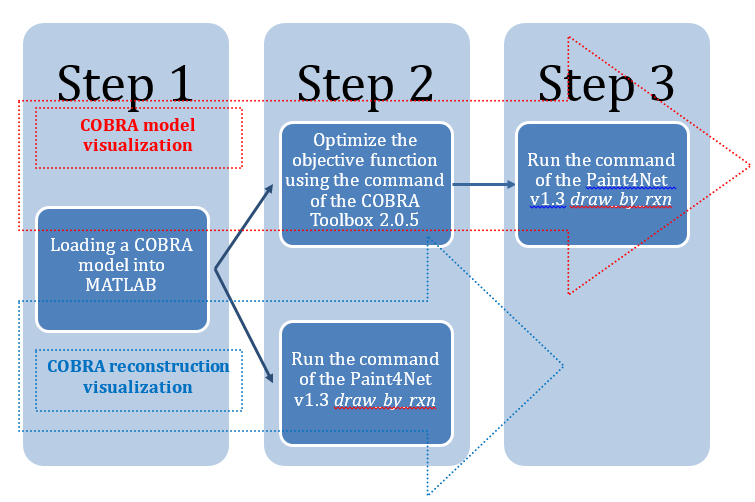

**Fig. 2.** The scenarios of an application of the command *draw_by_rxn*.

## *A****.**** COBRA model visualization* 

**i.** a COBRA model has to be loaded into MATLAB. 

**ii.** optimization of the objective function by using the COBRA toolbox command *optimizeCbModel, *where the argument *model* corresponds to the COBRA model in the MATLAB workspace.

FBAsolution = optimizeCbModel(model)

FBAsolution = struct with fields:
           x: [75×1 double]
           f: 0
           y: [60×1 double]
           w: [75×1 double]
        stat: 1
    origStat: 5
      solver: 'glpk'
        time: 0.0060
           v: [75×1 double]


This step ensures that a vector of the steady state fluxes *x* will be available for the command *draw_by_rxn*.

FBAsolution.x

ans =            0
           0
           0
       -1000
        1000
           0
         500
           0
           0
           0


**iii.** execution of the command *[involvedMets, deadEnds] = draw_by_rxn (model, rxns, drawMap, direction, initialMet, excludeMets, flux)*.

[Involved_mets, Dead_ends] = draw_by_rxn(model, model.rxns, 'true', 'struc', {''}, {''}, FBAsolution.x)

Start_time = '2017_7_5_15_49_0.357'

End_time = '2017_7_5_15_49_1.147'

Total_time = '0_0_0_0_0_0.79'

Involved_mets = 60×1 cell array
    'f6p[c]'
    'g6p[c]'
    'atp[c]'
    'glc-D[c]'
    'adp[c]'
    'h[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nad[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'dgp[c]'
    'co2[c]'
    'ru5p-D[c]'
    'xu5p-D[c]'
    'e4p[c]'
    'g3p[c]'
    'r5p[c]'
    's7p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    '2pg[c]'
    'pep[c]'
    'acald[c]'
    'coa[c]'
    'accoa[c]'
    'etoh[c]'
    'ac[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'o2[c]'
    'fum[c]'
    'succ[c]'
    'oaa[c]'
    'cit[c]'
    'cis-aconitate[c]'
    'icit-D[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc3p[c]'
    'glyc-R[c]'
    'glyc[c]'
    'dha[c]'
    'xyl-D[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    'glcn[c]'
    '2dhglcn[c]'
    'sbt-D[c]'


Dead_ends = 2×1 cell array
    'o2[c]'
    'xyl-D[c]'


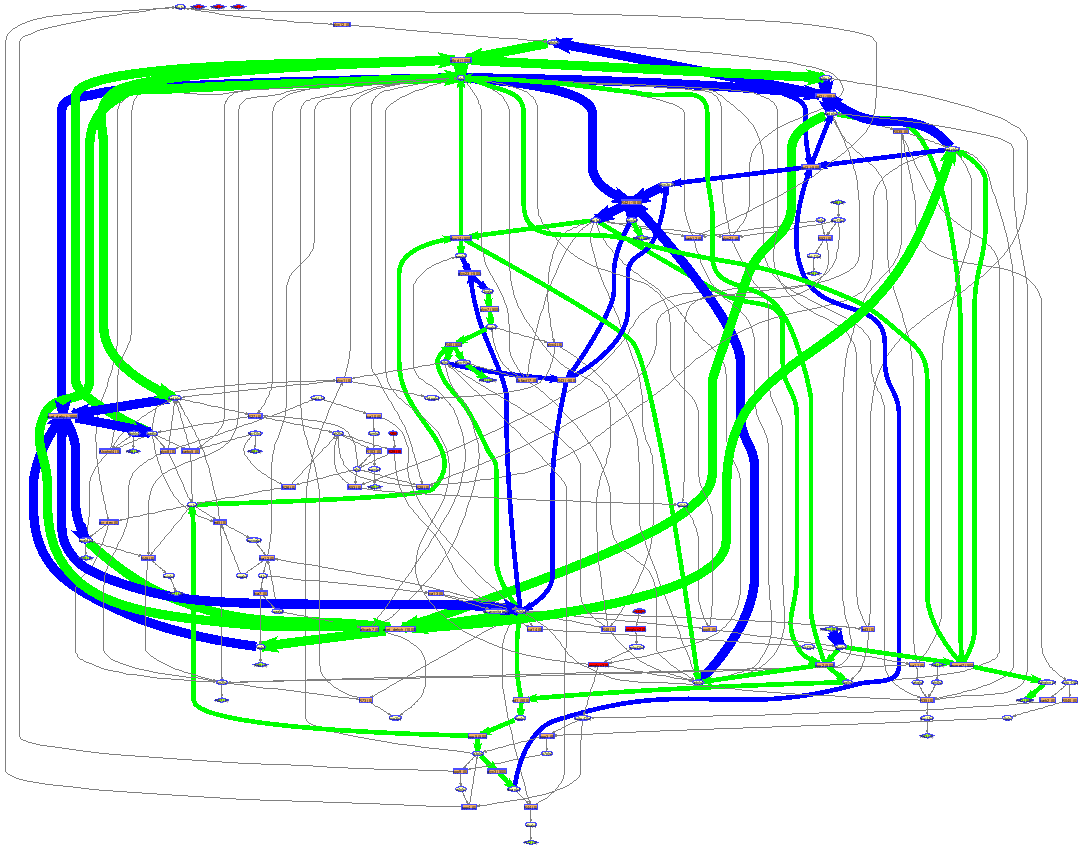

## *B.  COBRA reconstruction visualization* 

**i.** a COBRA model has to be loaded into MATLAB.

**ii.** execution of the command *[involvedMets, deadEnds] = draw_by_rxn (model, rxns, drawMap, direction, initialMet, excludeMets, flux)*

[involvedMets, deadEnds] = draw_by_rxn(model, model.rxns, 'true')

Start_time = '2017_7_5_15_49_1.175'

End_time = '2017_7_5_15_49_1.971'

Total_time = '0_0_0_0_0_0.796'

involvedMets = 60×1 cell array
    'f6p[c]'
    'g6p[c]'
    'atp[c]'
    'glc-D[c]'
    'adp[c]'
    'h[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nad[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'dgp[c]'
    'co2[c]'
    'ru5p-D[c]'
    'xu5p-D[c]'
    'e4p[c]'
    'g3p[c]'
    'r5p[c]'
    's7p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    '2pg[c]'
    'pep[c]'
    'acald[c]'
    'coa[c]'
    'accoa[c]'
    'etoh[c]'
    'ac[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'o2[c]'
    'fum[c]'
    'succ[c]'
    'oaa[c]'
    'cit[c]'
    'cis-aconitate[c]'
    'icit-D[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc3p[c]'
    'glyc-R[c]'
    'glyc[c]'
    'dha[c]'
    'xyl-D[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    'glcn[c]'
    '2dhglcn[c]'
    'sbt-D[c]'


deadEnds = 3×1 cell array
    'glc-D[c]'
    'o2[c]'
    'xyl-D[c]'


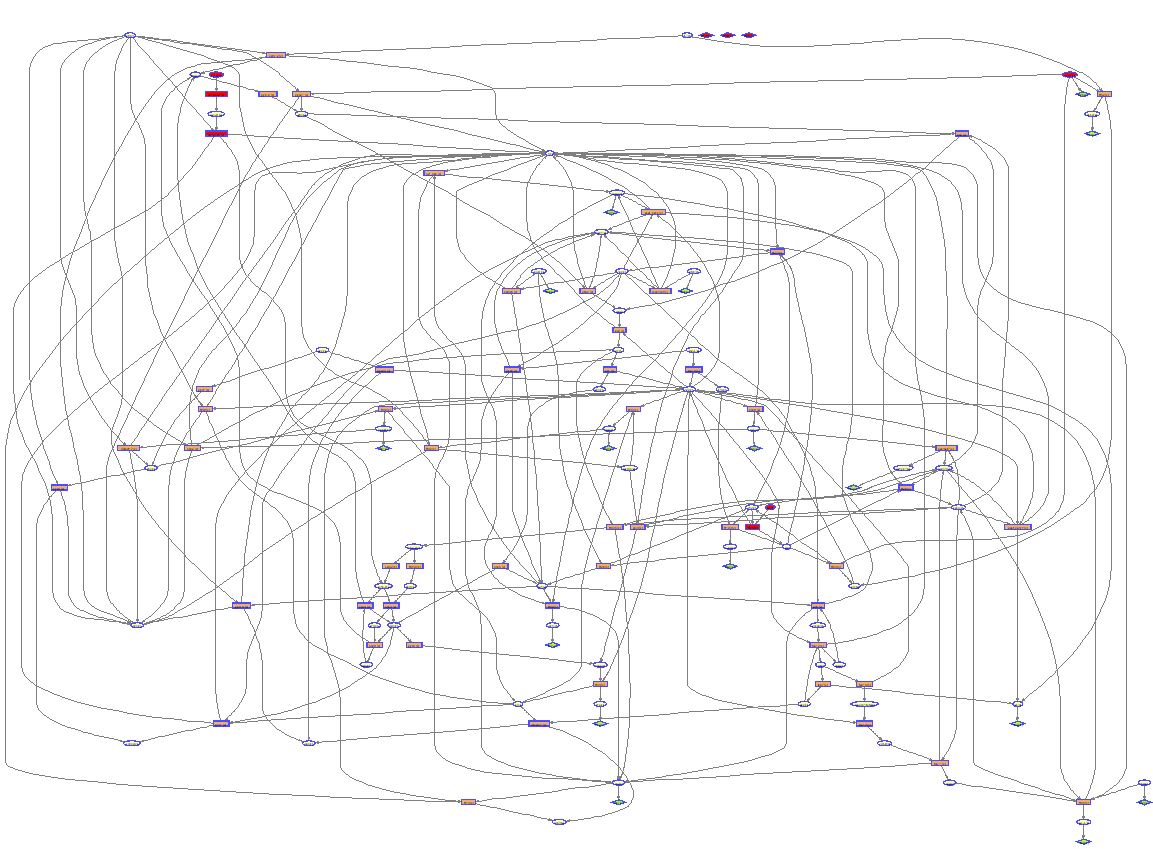

In this case in the brackets in the rectangles are shown characters *x* indicating that fluxes at steady state were not calculated. This approach is useful in case of reconstruction visualization where fluxes are not calculated. The arrows in the end of the edges point on the forward directions of the reactions in the COBRA model.

## ***Input arguments of the command draw_by_rxn***

The command *draw_by_rxn* has several input arguments – *model, rxns*,* drawMap*, *direction*, *initialMet*, *excludeMets*, and* flux*. The last 5 arguments are optional; it means that the algorithm of the command *draw_by_rxn* uses default values of those arguments, so user can ignore them if additional functionality is not actual.

**i. argument***** model***

This argument stands for a COBRA model in the MATLAB workspace.

**ii. argument***** rxns***

This argument represents a list of reactions from a COBRA model separated by a comma. The layout of map depends on this list, as a result if new abbreviation is added or some deleted in the list the layout will change as well. To prevent layout change by potential mistakes and save time by not creating the list every time from scratch it is possible to create a *cell *type vector in the MATLAB workspace that contains the static abbreviations of the reactions in the COBRA model and use it as argument *rxns*. 

rxns = {'glyc12', 'glyc21', 'carb12', 'ed2'}

rxns = 1×4 cell array
    'glyc12'    'glyc21'    'carb12'    'ed2'



[involvedMets, deadEnds] = draw_by_rxn(model, rxns)

Start_time = '2017_7_5_15_49_2.014'

End_time = '2017_7_5_15_49_2.392'

Total_time = '0_0_0_0_0_0.378'

involvedMets = 10×1 cell array
    'f6p[c]'
    'g6p[c]'
    'atp[c]'
    'glc-D[c]'
    'adp[c]'
    'h[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'


deadEnds = 5×1 cell array
    'glc-D[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'


Another example is a list of reaction in the COBRA model which can be accessed by *model.rxns*. It illustrates all COBRA model.

[involvedMets, deadEnds] = draw_by_rxn(model, model.rxns)

Start_time = '2017_7_5_15_49_2.422'

End_time = '2017_7_5_15_49_3.283'

Total_time = '0_0_0_0_0_0.861'

involvedMets = 60×1 cell array
    'f6p[c]'
    'g6p[c]'
    'atp[c]'
    'glc-D[c]'
    'adp[c]'
    'h[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nad[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'dgp[c]'
    'co2[c]'
    'ru5p-D[c]'
    'xu5p-D[c]'
    'e4p[c]'
    'g3p[c]'
    'r5p[c]'
    's7p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    '2pg[c]'
    'pep[c]'
    'acald[c]'
    'coa[c]'
    'accoa[c]'
    'etoh[c]'
    'ac[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'o2[c]'
    'fum[c]'
    'succ[c]'
    'oaa[c]'
    'cit[c]'
    'cis-aconitate[c]'
    'icit-D[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc3p[c]'
    'glyc-R[c]'
    'glyc[c]'
    'dha[c]'
    'xyl-D[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    'glcn[c]'
    '2dhglcn[c]'
    'sbt-D[c]'


deadEnds = 3×1 cell array
    'glc-D[c]'
    'o2[c]'
    'xyl-D[c]'


**iii. argument** ***drawMap***

It is a *logical* type variable that can take value of *'true*' or *'false'* (default is *'false*') indicating whether to visualize the COBRA model or not. The main idea of this argument is to ensure possibility to save time by not visualizing a large COBRA model and get a result faster.

[involvedMets, deadEnds] = draw_by_rxn(model, model.rxns, 'false')

Start_time = '2017_7_5_15_49_3.324'

End_time = '2017_7_5_15_49_4.073'

Total_time = '0_0_0_0_0_0.749'

involvedMets = 60×1 cell array
    'f6p[c]'
    'g6p[c]'
    'atp[c]'
    'glc-D[c]'
    'adp[c]'
    'h[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nad[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'dgp[c]'
    'co2[c]'
    'ru5p-D[c]'
    'xu5p-D[c]'
    'e4p[c]'
    'g3p[c]'
    'r5p[c]'
    's7p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    '2pg[c]'
    'pep[c]'
    'acald[c]'
    'coa[c]'
    'accoa[c]'
    'etoh[c]'
    'ac[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'o2[c]'
    'fum[c]'
    'succ[c]'
    'oaa[c]'
    'cit[c]'
    'cis-aconitate[c]'
    'icit-D[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc3p[c]'
    'glyc-R[c]'
    'glyc[c]'
    'dha[c]'
    'xyl-D[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    'glcn[c]'
    '2dhglcn[c]'
    'sbt-D[c]'


deadEnds = 3×1 cell array
    'glc-D[c]'
    'o2[c]'
    'xyl-D[c]'


**iiii. optional argument *****direction***

It is a *string* type variable that can take value of *'struc'*, *'sub'*, *'prod'* or *'both'* (default is *'struc'*) indicating a direction for the algorithm of the command *draw_by_rxn.*

[Involved_mets, Dead_ends] = draw_by_rxn(model, model.rxns, 'false', 'struc')

Start_time = '2017_7_5_15_49_4.102'

End_time = '2017_7_5_15_49_4.86'

Total_time = '0_0_0_0_0_0.758'

Involved_mets = 60×1 cell array
    'f6p[c]'
    'g6p[c]'
    'atp[c]'
    'glc-D[c]'
    'adp[c]'
    'h[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nad[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'dgp[c]'
    'co2[c]'
    'ru5p-D[c]'
    'xu5p-D[c]'
    'e4p[c]'
    'g3p[c]'
    'r5p[c]'
    's7p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    '2pg[c]'
    'pep[c]'
    'acald[c]'
    'coa[c]'
    'accoa[c]'
    'etoh[c]'
    'ac[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'o2[c]'
    'fum[c]'
    'succ[c]'
    'oaa[c]'
    'cit[c]'
    'cis-aconitate[c]'
    'icit-D[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc3p[c]'
    'glyc-R[c]'
    'glyc[c]'
    'dha[c]'
    'xyl-D[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    'glcn[c]'
    '2dhglcn[c]'
    'sbt-D[c]'


Dead_ends = 3×1 cell array
    'glc-D[c]'
    'o2[c]'
    'xyl-D[c]'


In case of *'struc'* (structure) the algorithm visualizes all metabolites connected to the specified reactions in the argument *rxns*. The key feature of this function is visualization of all specified reactions not taking in account a steady state fluxes in that way representing the structure of the COBRA model. In case of *'sub'* (substrates) the algorithm visualizes only those metabolites which are substrates for the specified reactions in the argument *rxns*. This time the algorithm is using a stoichiometric matrix and the steady state fluxes to determine direction of each reaction. The algorithm is using an assumption that only those fluxes which rates are smaller than -10-9 mmol*g-1*h-1or greater than +10-9 mmol*g-1*h-1 are non-zero fluxes. In case of *'prod'* (products) the algorithm visualizes only those metabolites which are products for the specified reactions in the argument *rxns* but in case of *'both' *the algorithm visualizes both – substrates and products - for the specified reactions in the argument *rxns*. For both cases the algorithm is using the same rules regarding to calculation of the directions for each reaction as for case of *'sub'*. This argument is essential for the command *draw_by_met * of the Paint4Net v1.3 because the command *draw_by_met* is calling out the command *draw_by_rxn *and passing the argument *direction*.

**iiiii. optional argument *****initialMet***

It is a *cell* type variable that can take a value that represents the abbreviation of a metabolite in the COBRA model (default is empty).

[Involved_mets, Dead_ends] = draw_by_rxn(model, model.rxns, 'true', 'struc', {'atp[c]'}, {''}, FBAsolution.x)

Start_time = '2017_7_5_15_49_4.892'

End_time = '2017_7_5_15_49_5.769'

Total_time = '0_0_0_0_0_0.877'

Involved_mets = 60×1 cell array
    'f6p[c]'
    'g6p[c]'
    'atp[c]'
    'glc-D[c]'
    'adp[c]'
    'h[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nad[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'dgp[c]'
    'co2[c]'
    'ru5p-D[c]'
    'xu5p-D[c]'
    'e4p[c]'
    'g3p[c]'
    'r5p[c]'
    's7p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    '2pg[c]'
    'pep[c]'
    'acald[c]'
    'coa[c]'
    'accoa[c]'
    'etoh[c]'
    'ac[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'o2[c]'
    'fum[c]'
    'succ[c]'
    'oaa[c]'
    'cit[c]'
    'cis-aconitate[c]'
    'icit-D[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc3p[c]'
    'glyc-R[c]'
    'glyc[c]'
    'dha[c]'
    'xyl-D[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    'glcn[c]'
    '2dhglcn[c]'
    'sbt-D[c]'


Dead_ends = 2×1 cell array
    'o2[c]'
    'xyl-D[c]'


This metabolite is represented as green ellipse on the map (see Fig. 3) and this feature is essential for the command *draw_by_met *of the Paint4Net v1.3 because the command *draw_by_met* is calling out the command *draw_by_rxn* and passing the argument *initialMet*.

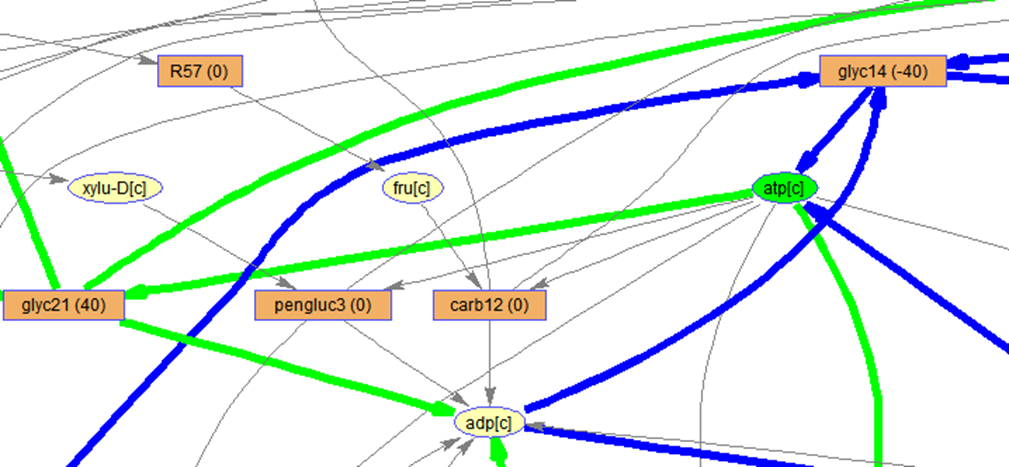

**Fig. 3.**The metabolite *atp[c]* as initial metabolite on the map of the COBRA model.

**iiiiii. optional argument *****excludeMets***

This argument represents a list of metabolites (default is empty) that will be excluded from the visualization map of the COBRA model in form of the abbreviations of the metabolites separated by a comma. To save time by not creating the list every time from scratch it is possible to create a *cell *type vector in the MATLAB workspace that contains the static abbreviations of the metabolites in the COBRA model and use it as argument *excludeMets*. 

excludeMets = {'atp[c]', 'nad[c]', 'adp[c]', 'h[c]'}

excludeMets = 1×4 cell array
    'atp[c]'    'nad[c]'    'adp[c]'    'h[c]'


[Involved_mets, Dead_ends] = draw_by_rxn(model, model.rxns, 'true', 'struc', {''}, excludeMets)

Start_time = '2017_7_5_15_49_5.811'

End_time = '2017_7_5_15_49_6.792'

Total_time = '0_0_0_0_0_0.981'

Involved_mets = 56×1 cell array
    'f6p[c]'
    'g6p[c]'
    'glc-D[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'dgp[c]'
    'co2[c]'
    'ru5p-D[c]'
    'xu5p-D[c]'
    'e4p[c]'
    'g3p[c]'
    'r5p[c]'
    's7p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    '2pg[c]'
    'pep[c]'
    'acald[c]'
    'coa[c]'
    'accoa[c]'
    'etoh[c]'
    'ac[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'o2[c]'
    'fum[c]'
    'succ[c]'
    'oaa[c]'
    'cit[c]'
    'cis-aconitate[c]'
    'icit-D[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc3p[c]'
    'glyc-R[c]'
    'glyc[c]'
    'dha[c]'
    'xyl-D[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    'glcn[c]'
    '2dhglcn[c]'
    'sbt-D[c]'


Dead_ends = 3×1 cell array
    'glc-D[c]'
    'o2[c]'
    'xyl-D[c]'


The main idea of this argument is to ensure possibility to exclude very employed metabolites (e.g., h, h2o, atp, adp, nad etc.) to avoid unnecessary mesh on the map (see Fig. 4, Fig. 5, Fig. 6, Fig. 7, Fig. 8 and Fig. 9).

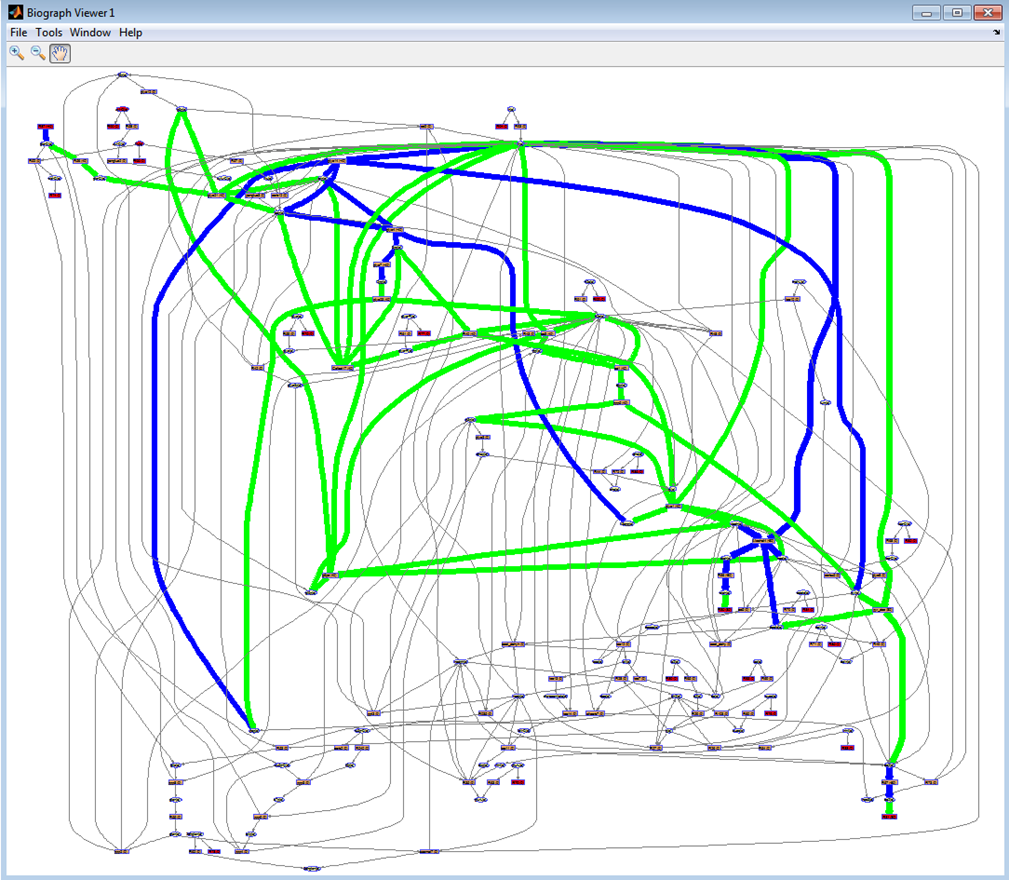

**Fig. 4.** An example of the map of the COBRA model. Full scope.

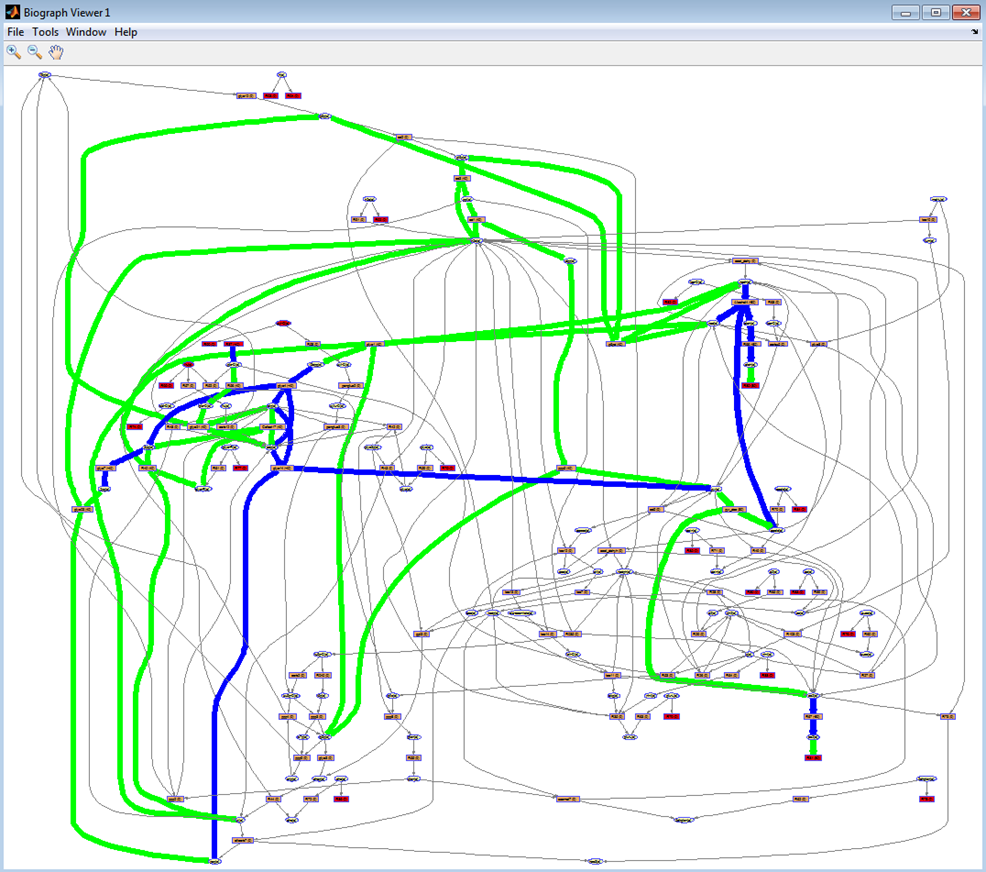

**Fig. 5.** An example of the map of the COBRA model. The metabolite *h[c]* is excluded from map which reduce the number of edges by 26.

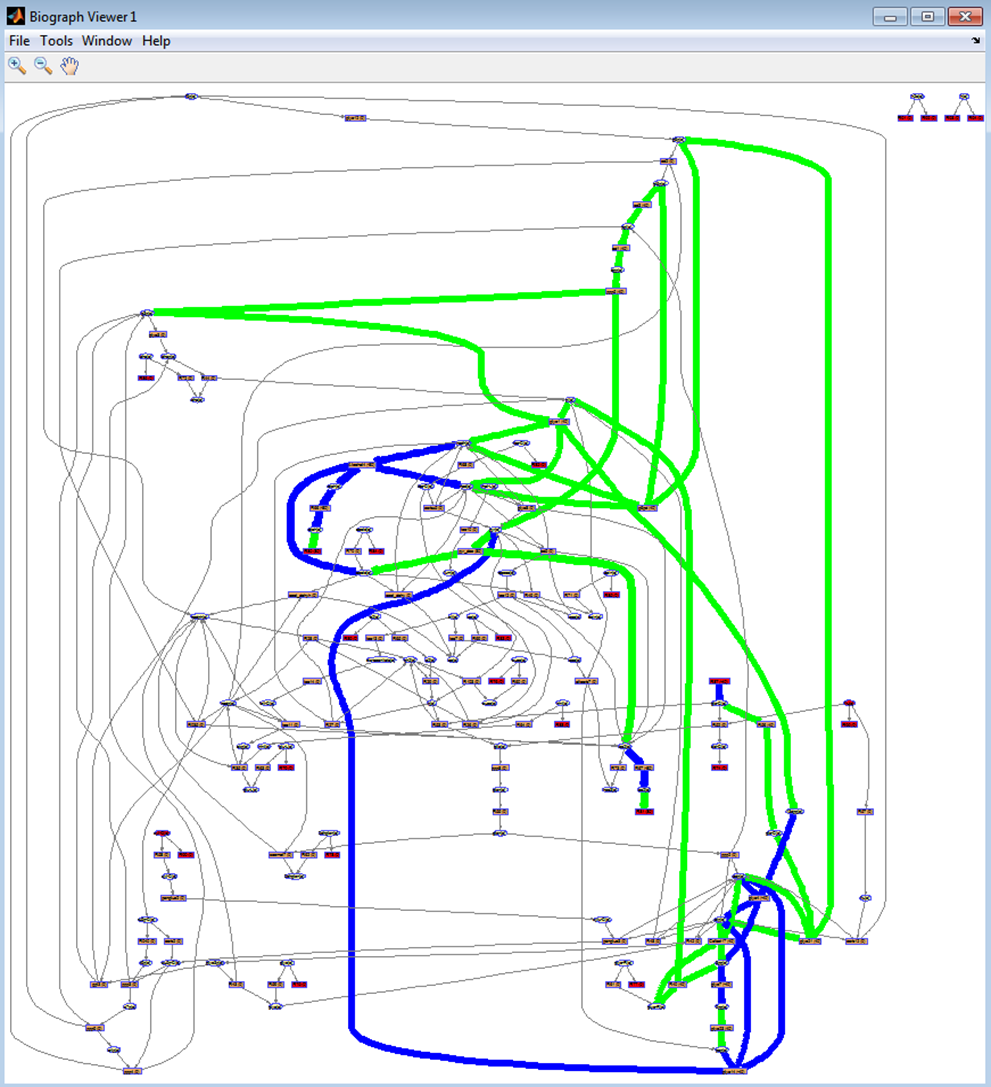

**Fig. 6.** An example of the map of the COBRA model. The metabolites *h[c]*, and *h2o[c]* are excluded from map which reduce the number of edges by 26+17=43.

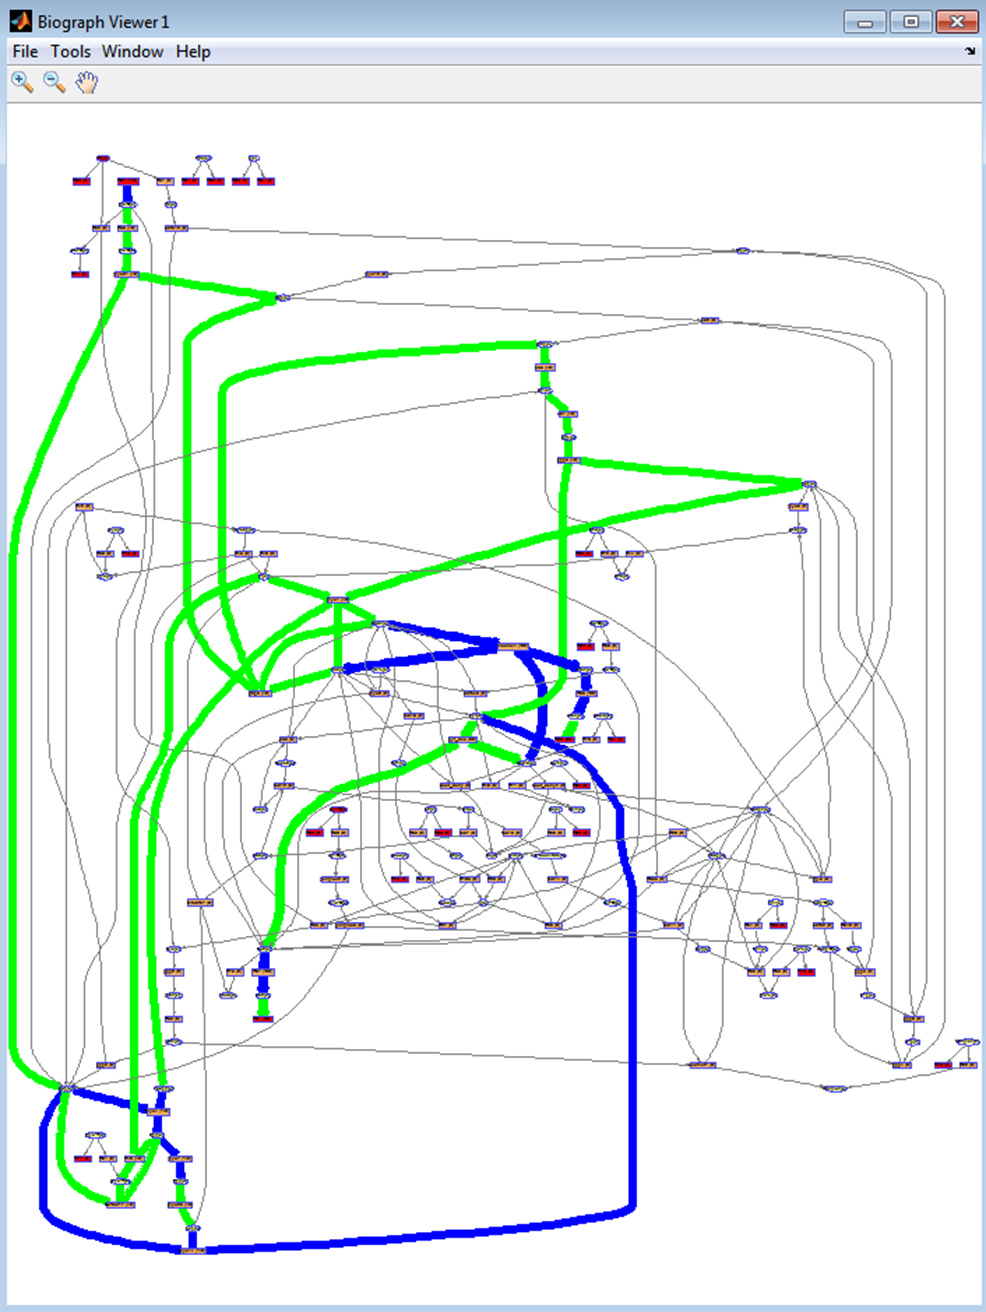

**Fig. 7. **An example of the map of the COBRA model. The metabolites *h[c]*, *h2o[c]*, and *atp[c]* are excluded from map which reduce the number of edges by 26+17+9=52.

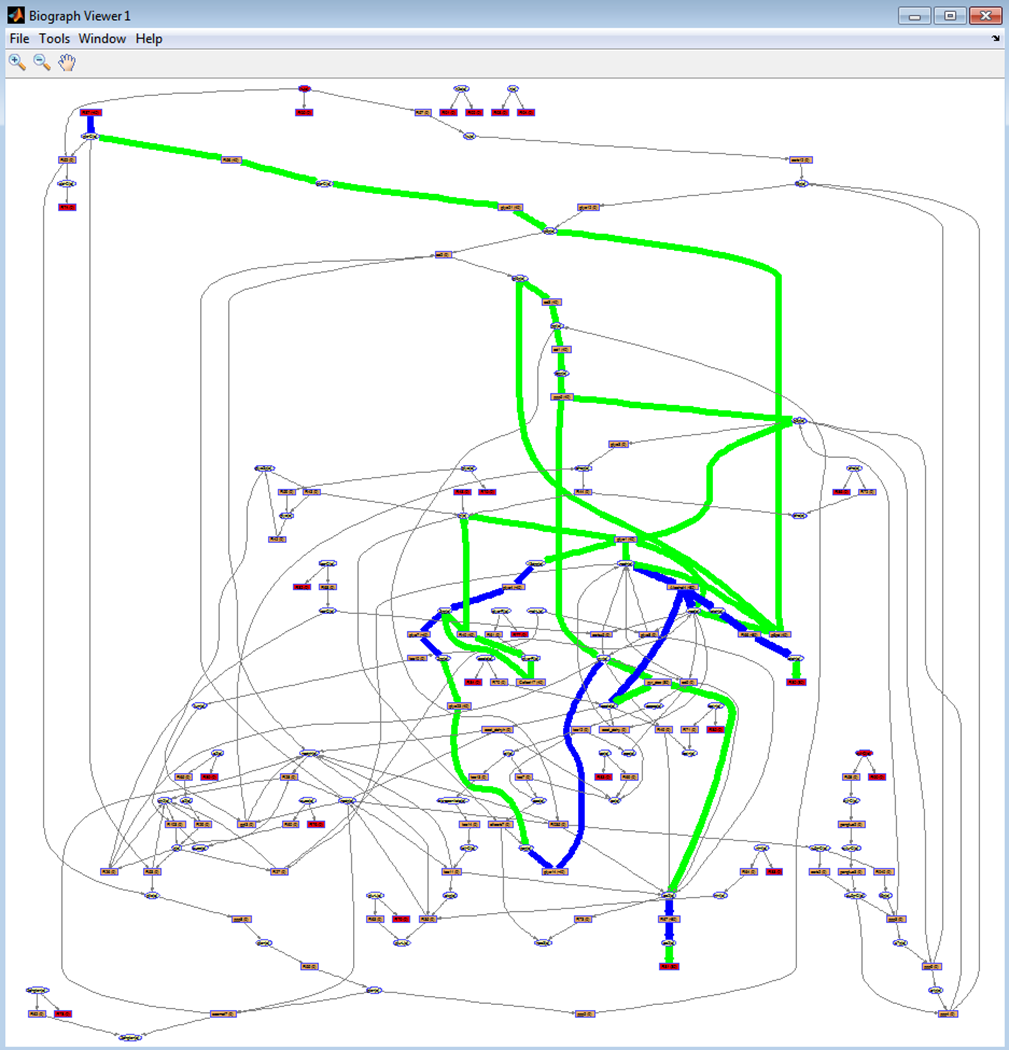

**Fig. 8.** An example of the map of the COBRA model. The metabolites *h[c]*, *h2o[c]*, *atp[c]*, and *adp[c]* are excluded from map which reduce the number of edges by 26+17+9+9=61.

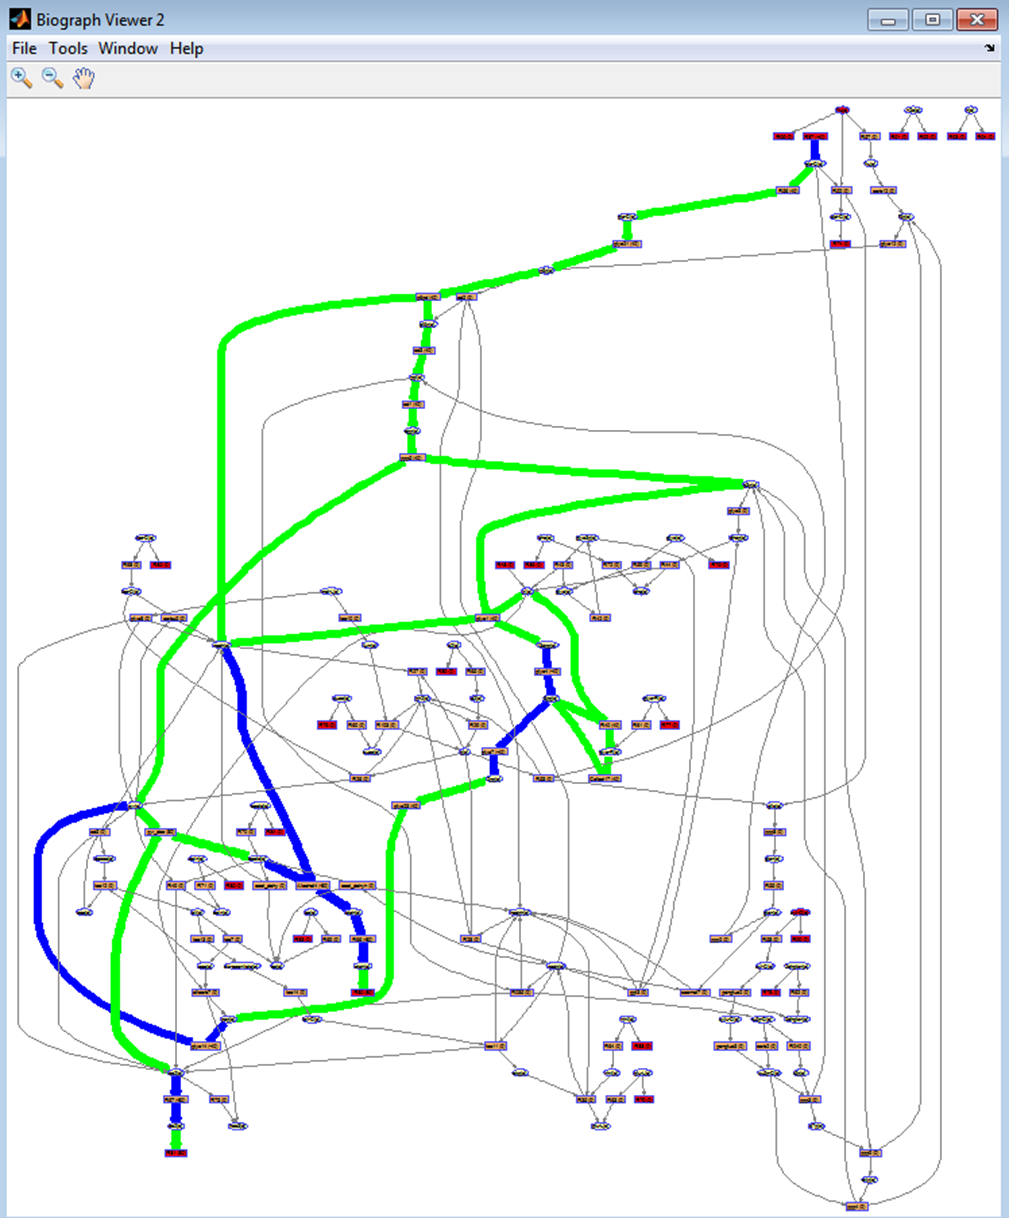

**Fig. 9.** An example of the map of the COBRA model. The metabolites *h[c]*, *h2o[c]*, *atp[c]*, *adp[c]*, and *nad[c]* are excluded from map which reduce the number of edges by 26+17+9+9+8=69.

**iiiiiii. optional argument *****flux***

It is a *double* type Nx1 size vector of fluxes of reactions where N is number of reactions (default is vector of x). This vector is calculated during the optimization of the objective function and can be accessed through the result of the optimization command.

FBAsolution.x

ans =            0
           0
           0
       -1000
        1000
           0
         500
           0
           0
           0


## ***Output of the command draw_by_rxn***

The command *draw_by_rxn *has two output vectors in the result: *involvedMets *and *deadEnds*.

**i. the vector *****involvedMets***

It is a *cell *type vector that contains a list of the involved metabolites in the specified reactions (see Fig. 10).

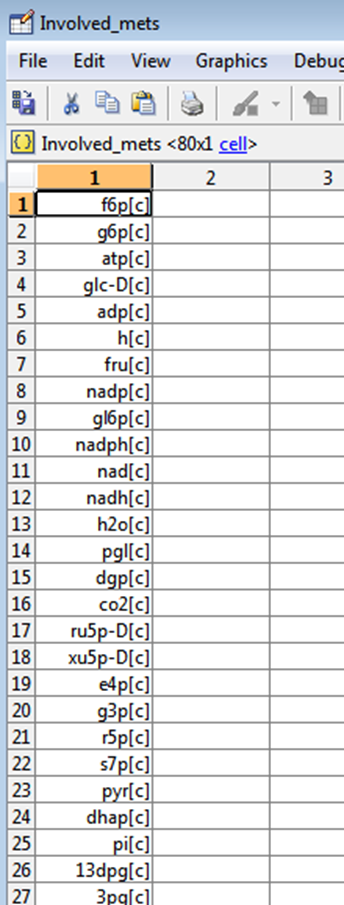

**Fig. 10.** An example of the list of the involved metabolites.

**ii. the vector *****deadEnds***

It is also a *cell *type vector but it contains a list of the dead end metabolites in the specified reactions (see Fig. 11).

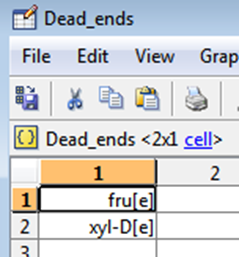

**Fig. 11. **An example of the list of the dead end metabolites.

## *Application of command**** draw_by_met*** 

***draw_by_met*** can be used can be performed using **option** **A** in case COBRA model with optimization results have to be visualized or **option B** if the interconnections between metabolites in COBRA file have to be visualized (See Fig. 12).

 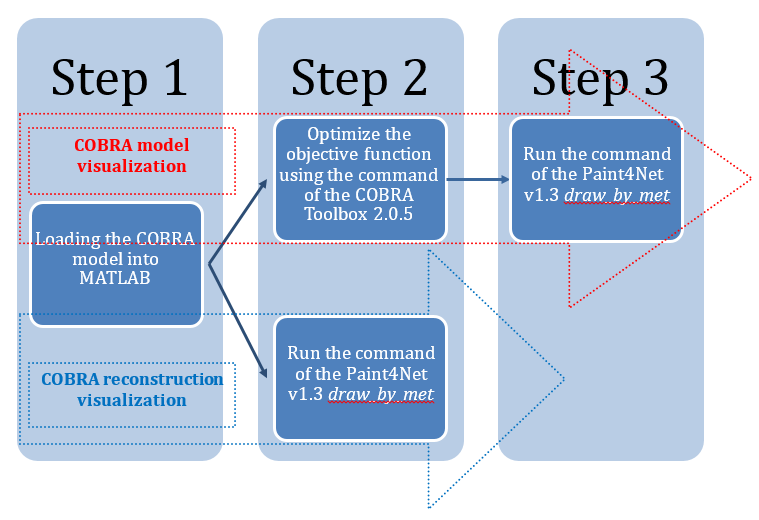

**Fig. 12. **The scenarios of an application of the command *draw_by_met*.

## *A. COBRA model visualization* 

**i.** a COBRA model has to be loaded into MATLAB. 

**ii.** optimization of the objective function by using the COBRA toolbox command *optimizeCbModel, *where the argument *model* corresponds to the COBRA model in the MATLAB workspace.

FBAsolution = optimizeCbModel(model)

FBAsolution = struct with fields:
           x: [75×1 double]
           f: 0
           y: [60×1 double]
           w: [75×1 double]
        stat: 1
    origStat: 5
      solver: 'glpk'
        time: 0.0090
           v: [75×1 double]


This step ensures that a vector of the steady state fluxes *x* will be available for the command *draw_by_met*.

FBAsolution.x

ans =            0
           0
           0
       -1000
        1000
           0
         500
           0
           0
           0


**iii.** execution of the command [directionRxns, involvedMets, deadEnds] = draw_by_met(model, metAbbr, drawMap, radius, direction, excludeMets, flux).

[directionRxns, involvedMets, deadEnds] = draw_by_met(model, {'etoh[c]'}, 'true', 2, 'struc', {''}, FBAsolution.x)

Start_time = '2017_7_5_15_49_6.898'

End_time = '2017_7_5_15_49_7.467'

Total_time = '0_0_0_0_0_0.569'

directionRxns = 30×1 cell array
    'Alcohol4'
    'R66'
    'glyc21'
    'carb12'
    'ed2'
    'g6pd'
    'ed3'
    'glyc1'
    'glyc14'
    'pyr_dec'
    'ed5'
    'acet_dehy'
    'acet_dehyh'
    'carbx5'
    'R27'
    'R28'
    'tca12'
    'R35'
    'glyc8'
    'gpl3'
    'Cofact17'
    'R42'
    'pengluc3'
    'R48'
    'R49'
    'ppp8'
    'secmet7'
    'ppp2'
    'R70'
    'R73'


involvedMets = 46×1 cell array
    'f6p[c]'
    'g6p[c]'
    'atp[c]'
    'glc-D[c]'
    'adp[c]'
    'h[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nad[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'co2[c]'
    'xu5p-D[c]'
    'g3p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    'pep[c]'
    'acald[c]'
    'coa[c]'
    'accoa[c]'
    'etoh[c]'
    'ac[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'oaa[c]'
    'cit[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc3p[c]'
    'glyc-R[c]'
    'glyc[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    'glcn[c]'
    '2dhglcn[c]'


deadEnds = 25×1 cell array
    'f6p[c]'
    'glc-D[c]'
    'fru[c]'
    'xu5p-D[c]'
    'g3p[c]'
    'dhap[c]'
    '13dpg[c]'
    '3pg[c]'
    'pep[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'oaa[c]'
    'cit[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc-R[c]'
    'glyc[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    '2dhglcn[c]'


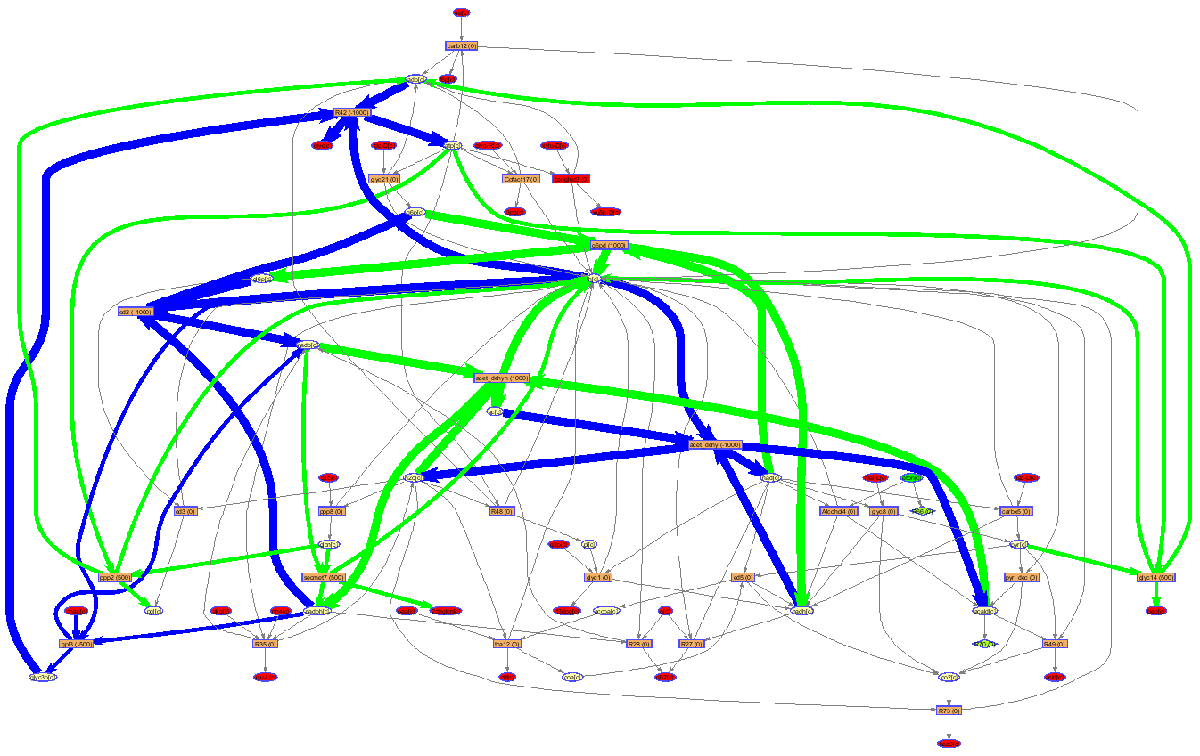

## *B.  COBRA reconstruction visualization*

**i.** a COBRA model has to be loaded into MATLAB. 

**ii.** execution of the command [directionRxns, involvedMets, deadEnds] = draw_by_met(model, metAbbr, drawMap, radius, direction, excludeMets, flux)

[directionRxns, involvedMets, deadEnds] = draw_by_met(model, {'etoh[c]'}, 'true', 2)

Start_time = '2017_7_5_15_49_7.502'

End_time = '2017_7_5_15_49_8.198'

Total_time = '0_0_0_0_0_0.696'

directionRxns = 30×1 cell array
    'Alcohol4'
    'R66'
    'glyc21'
    'carb12'
    'ed2'
    'g6pd'
    'ed3'
    'glyc1'
    'glyc14'
    'pyr_dec'
    'ed5'
    'acet_dehy'
    'acet_dehyh'
    'carbx5'
    'R27'
    'R28'
    'tca12'
    'R35'
    'glyc8'
    'gpl3'
    'Cofact17'
    'R42'
    'pengluc3'
    'R48'
    'R49'
    'ppp8'
    'secmet7'
    'ppp2'
    'R70'
    'R73'


involvedMets = 46×1 cell array
    'f6p[c]'
    'g6p[c]'
    'atp[c]'
    'glc-D[c]'
    'adp[c]'
    'h[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nad[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'co2[c]'
    'xu5p-D[c]'
    'g3p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    'pep[c]'
    'acald[c]'
    'coa[c]'
    'accoa[c]'
    'etoh[c]'
    'ac[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'oaa[c]'
    'cit[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc3p[c]'
    'glyc-R[c]'
    'glyc[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    'glcn[c]'
    '2dhglcn[c]'


deadEnds = 25×1 cell array
    'f6p[c]'
    'glc-D[c]'
    'fru[c]'
    'xu5p-D[c]'
    'g3p[c]'
    'dhap[c]'
    '13dpg[c]'
    '3pg[c]'
    'pep[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'oaa[c]'
    'cit[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc-R[c]'
    'glyc[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    '2dhglcn[c]'


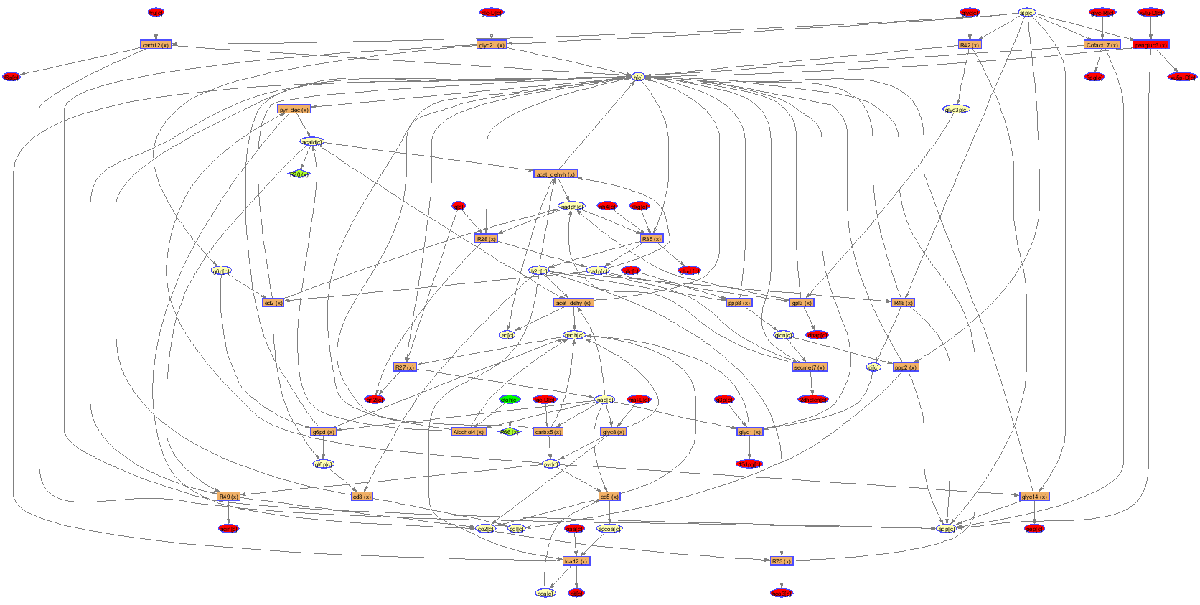

In this case in the brackets in the rectangles are shown characters *x*indicating that fluxes at steady state were not calculated. This approach is useful in case of reconstruction visualization where fluxes are not calculated.

## **Input arguments of the command *****draw_by_met***

The command *draw_by_met *has several input arguments – *model, **metAbbr**, drawMap, radius, direction, excludeMets, *and *flux*. The last 5 are optional, it means that the algorithm of the command *draw_by_met *uses default values of those arguments, so user can ignore them if additional functionality is not necessary.

**i. argument *****model***

This argument stands for a COBRA model in the MATLAB workspace.

**ii. argument *****metAbbr***

It is a *cell *type variable that can take a value that represents the abbreviation of a metabolite in a COBRA model. This argument is the start point for the algorithm of the command *draw_by_met* for visualization.

[directionRxns, involvedMets, deadEnds] = draw_by_met(model, {'etoh[c]'})

Start_time = '2017_7_5_15_49_8.242'

End_time = '2017_7_5_15_49_8.559'

Total_time = '0_0_0_0_0_0.317'

directionRxns = 2×1 cell array
    'Alcohol4'
    'R66'


involvedMets = 5×1 cell array
    'h[c]'
    'nad[c]'
    'nadh[c]'
    'acald[c]'
    'etoh[c]'


deadEnds = 4×1 cell array
    'h[c]'
    'nad[c]'
    'nadh[c]'
    'acald[c]'


**iii. optional argument *****drawMap***

It is a *logical* type variable that can take value of *'true'* or *'false*' (default is *'false'*) indicating whether to visualize the COBRA model or not*. *The main idea of this argument is to ensure possibility to save time by not visualizing a large COBRA model and get a result  faster.

[directionRxns, involvedMets, deadEnds] = draw_by_met(model, {'etoh[c]'}, 'true')

Start_time = '2017_7_5_15_49_8.587'

End_time = '2017_7_5_15_49_8.89'

Total_time = '0_0_0_0_0_0.303'

directionRxns = 2×1 cell array
    'Alcohol4'
    'R66'


involvedMets = 5×1 cell array
    'h[c]'
    'nad[c]'
    'nadh[c]'
    'acald[c]'
    'etoh[c]'


deadEnds = 4×1 cell array
    'h[c]'
    'nad[c]'
    'nadh[c]'
    'acald[c]'


**iiii. optional argument *****radius***

It is a *double* type variable that can take a value of natural numbers (1,2,3…n).

[directionRxns, involvedMets, deadEnds] = draw_by_met(model, {'etoh[c]'}, 'true', 1)

Start_time = '2017_7_5_15_49_8.93'

End_time = '2017_7_5_15_49_9.314'

Total_time = '0_0_0_0_0_0.384'

directionRxns = 2×1 cell array
    'Alcohol4'
    'R66'


involvedMets = 5×1 cell array
    'h[c]'
    'nad[c]'
    'nadh[c]'
    'acald[c]'
    'etoh[c]'


deadEnds = 4×1 cell array
    'h[c]'
    'nad[c]'
    'nadh[c]'
    'acald[c]'


The argument *radius *indicates the depth of an analysis of the initial metabolite (the argument *metAbbr*) and it is tightly connected to the optional argument *direction. *For example, if user is interested in the substrates of *ethanol*, the user can analyse substrates step by step starting from the first reactions where the argument *radius* is equal to 1 and moving to the next reactions by increasing the value of the argument *radius* (see Fig. 13 and Fig. 14).

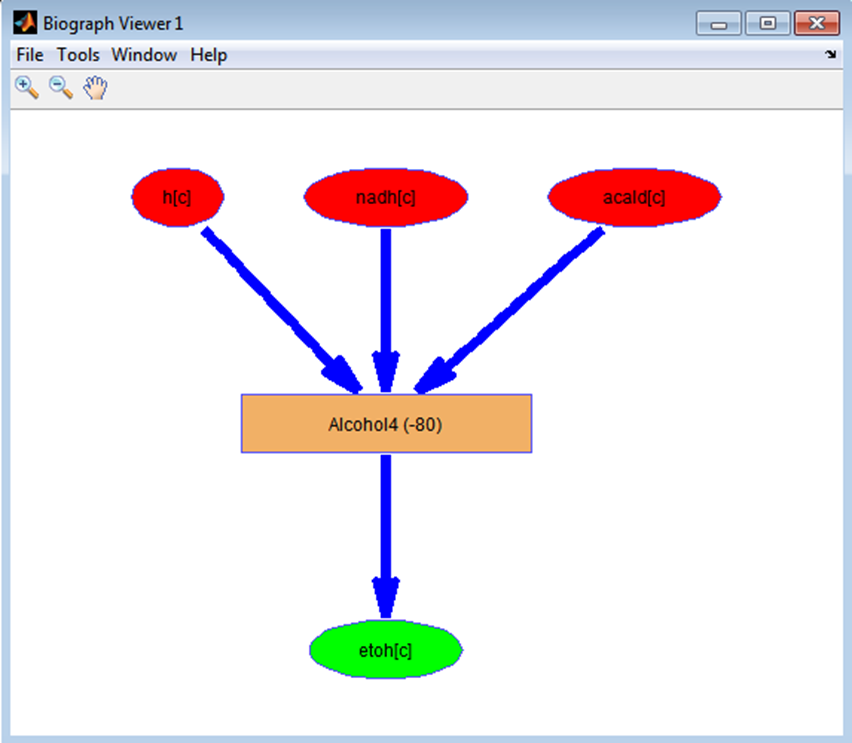

**Fig. 13.** Example where the argument *radius *= 1 (distance = one reaction from initial metabolite *etoh[c]*). In the reaction *Alchocol4* the metabolites *h[c]*, *nadh[c]*, and *acald[c]* are consumed and the metabolite *etoh[c] *is produced. The flux rate is -80 mmol*g-1*h-1that indicates that reaction is going backwards.

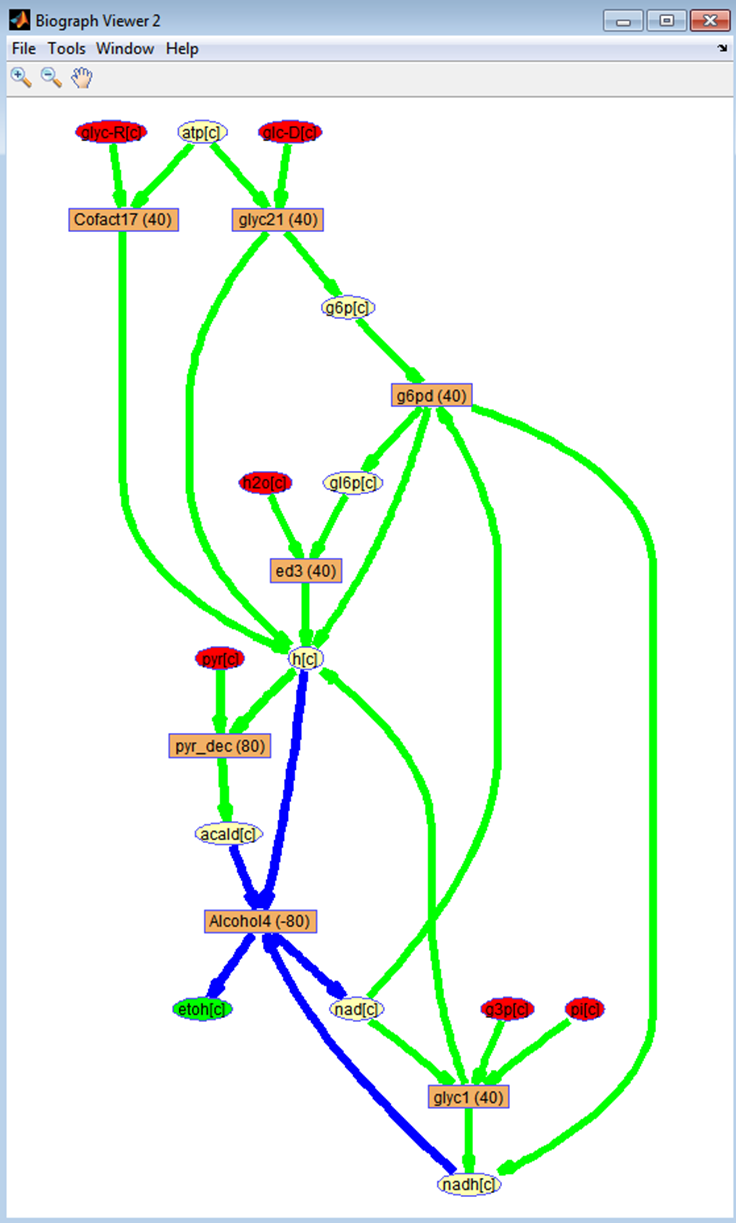

**Fig. 14.** Example where the argument *radius* = 2 (distance = two reactions from initial metabolite *etoh[c]*). The metabolites *glyc-R[c]*, *glc-D[c]*, *h2o[c]*, *pyr[c]*, *g3p[c]*, and *pi[c]* are consumed and the metabolite *etoh[c] *is produced.

The algorithm of the command *draw_by_met* interconnects all involved metabolites according to the stoichiometric matrix of a COBRA model. The important point to understand correctly is imbalance of the rates of fluxes in case of partial network. The algorithm of the command *draw_by_met* shows the rates of fluxes in the brackets in the rectangles according to steady state, but in case of visualization of partial network not all rectangles are seen which leads to imbalance for some metabolites. For example, in the Fig. 14 the metabolite *h[c]* is produced in 5 reactions (*Cofact17*, *glyc21*, *ed3*, *g6pd*, and *glyc1*) with total 5*40=200 mmol*g-1*h-1 but it is consumed in 2 reactions (*pyr_dec*and *Alchocol4*) with only 2*80 = 160 mmol*g-1*h-1.

**iiiii. optional argument *****direction***

It is a *string*type variable that can take value of *'struc'*, *'sub'*, *'prod'* or *'both'* (default is *'struc'*) indicating a direction for the algorithm of the command *draw_by_met. *In case of *'struc'* (structure) the algorithm visualizes all metabolites connected to the specified reactions in the argument *rxns*. The key feature of this function is visualization of all specified reactions not taking in account a steady state fluxes in that way representing the structure of the COBRA model. In case of *'sub'* (substrates) the algorithm visualizes only those metabolites which are substrates for the specified reactions in the argument *rxns*. This time the algorithm is using a stoichiometric matrix and the steady state fluxes to determine direction of each reaction. The algorithm is using an assumption that only those fluxes which rates are smaller than -10-9 mmol*g-1*h-1or greater than +10-9 mmol*g-1*h-1 are non-zero fluxes. In case of *'prod'* (products) the algorithm visualizes only those metabolites which are products for the specified reactions in the argument *rxns* but in case of *'both' *the algorithm visualizes both – substrates and products - for the specified reactions in the argument *rxns*. For both cases the algorithm is using the same rules regarding to calculation of the directions for each reaction as for case of *'sub'*.

**iiiiii. optional argument *****excludeMets***

This argument represents a list of metabolites (default is empty) that will be excluded from the visualization map of the COBRA model in form of the abbreviations of the metabolites separated by a comma. 

**iiiiiii. optional argument *****flux***

It is a *double* type Nx1 size vector of fluxes of reactions where N is number of reactions (default is vector of x). This vector is calculated during the optimization of the objective function and can be accessed through the result of the optimization command by *FBAsolution.x.* 

## *Output of the command draw_by_met *

The command *draw_by_met *has three output vectors in the result: *involvedRxns*,* involvedMets*, and *deadEnds*.

**i. vector *****involvedRxns***

It is a *cell *type vector that contains a list of the involved reactions according to the set of input arguments (see **Fig. 15**).

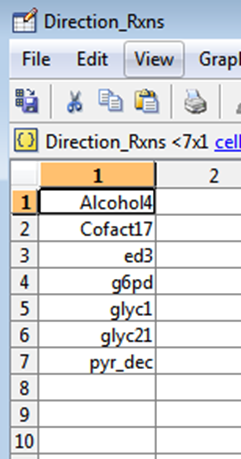

**Fig. 15. **An example of the list of the involved reactions.

**ii. vector *****involvedMets***

It is a *cell *type vector that contains a list of the involved metabolites in the specified reactions (see Fig. 10).

**iii. vector *****deadEnds***

It is also a *cell *type vector but it contains a list of the dead end metabolites in the specified reactions (see Fig. 11).

## TROUBLESHOOTING

**Problem: **output vectors ar valid, but visuaization layout is not generated.

**Possible reason: **the input argument *drawMap *is not provided properly.

**Solution: **It is a *logical* type variable that can take value of *'true'* or *'false*' (default is *'false'*) indicating whether to visualize the COBRA model or not. Please pay attention to single quotes around the argument.

## TIMING

Timing is given as Start_time, End_time and Total_time for every Paint4Net function call. It may varie based on equipment computing power.

## ANTICIPATED RESULTS	

**1. Load a model.**

The sample model is available at http://www.biosystems.lv/paint4net/sample_files.

model = xls2model('test_model.xls')

glyc12	f6p[c] 	->	g6p[c] 


glyc21	atp[c] + glc-D[c] 	->	g6p[c] + adp[c] + h[c] 


carb12	atp[c] + fru[c] 	<=>	f6p[c] + adp[c] + h[c] 


ed2	g6p[c] + nadp[c] 	<=>	h[c] + gl6p[c] + nadph[c] 


g6pd	g6p[c] + nad[c] 	<=>	h[c] + gl6p[c] + nadh[c] 


ed3	gl6p[c] + h2o[c] 	->	h[c] + pgl[c] 


ed1	pgl[c] 	<=>	h2o[c] + dgp[c] 


R035	nadp[c] + pgl[c] 	->	nadph[c] + co2[c] + ru5p-D[c] 


ppp4	xu5p-D[c] + e4p[c] 	<=>	f6p[c] + g3p[c] 


ppp3	xu5p-D[c] + r5p[c] 	<=>	g3p[c] + s7p[c] 
carb2	ru5p-D[c] 	<=>	xu5p-D[c] 
R040	ru5p-D[c] 	<=>	r5p[c] 


ppp5	dgp[c] 	<=>	g3p[c] + pyr[c] 


glyc3	g3p[c] 	<=>	dhap[c] 


glyc1	nad[c] + g3p[c] + pi[c] 	->	h[c] + nadh[c] + 13dpg[c] 


glyc4	atp[c] + 3pg[c] 	<=>	adp[c] + 13dpg[c] 


glyc7	2pg[c] 	<=>	3pg[c] 


glyc23	2pg[c] 	<=>	h2o[c] + pep[c] 
glyc14	atp[c] + pyr[c] 	<=>	adp[c] + h[c] + pep[c] 


pyr_dec	h[c] + pyr[c] 	->	co2[c] + acald[c] 


ed5	nad[c] + pyr[c] + coa[c] 	->	nadh[c] + co2[c] + accoa[c] 


Alcohol4	nad[c] + etoh[c] 	<=>	h[c] + nadh[c] + acald[c] 


acet_dehy	nad[c] + h2o[c] + acald[c] 	<=>	2 h[c] + nadh[c] + ac[c] 
acet_dehyh	nadp[c] + h2o[c] + acald[c] 	<=>	2 h[c] + nadph[c] + ac[c] 


carbx5	nad[c] + lac-D[c] 	<=>	h[c] + nadh[c] + pyr[c] 


R26	lac-D[c] + q[c] 	->	pyr[c] + qh2[c] 
R27	h[c] + nadh[c] + q[c] 	->	nad[c] + qh2[c] 
R28	h[c] + nadph[c] + q[c] 	->	nadp[c] + qh2[c] 


R29	2 qh2[c] + o2[c] 	->	2 h2o[c] + 2 q[c] 


R103	qh2[c] + fum[c] 	<=>	q[c] + succ[c] 


tca12	h2o[c] + accoa[c] + oaa[c] 	<=>	h[c] + coa[c] + cit[c] 
tca7	cit[c] 	<=>	ac[c] + oaa[c] 


tca13	cit[c] 	<=>	h2o[c] + cis-aconitate[c] 


tca14	h2o[c] + cis-aconitate[c] 	<=>	icit-D[c] 


tca11	nadp[c] + icit-D[c] 	->	nadph[c] + co2[c] + akg[c] 


R35	h[c] + nadph[c] + akg[c] + nh4[c] 	<=>	nadp[c] + h2o[c] + glu-L[c] 


tca10	mal-L[c] 	<=>	h2o[c] + fum[c] 
glyc8	nad[c] + mal-L[c] 	<=>	nadh[c] + co2[c] + pyr[c] 


altcarb7	pi[c] + oaa[c] 	<=>	pep[c] + hco3[c] 


gpl3	nadp[c] + glyc3p[c] 	<=>	h[c] + nadph[c] + dhap[c] 


R40	h2o[c] + 3pg[c] 	->	pi[c] + glyc-R[c] 
Cofact17	atp[c] + glyc-R[c] 	<=>	adp[c] + h[c] + 3pg[c] 


R42	atp[c] + glyc[c] 	<=>	adp[c] + h[c] + glyc3p[c] 
R43	h2o[c] + glyc3p[c] 	<=>	pi[c] + glyc[c] 


R44	h2o[c] + dhap[c] 	<=>	pi[c] + dha[c] 


pengluc2	xyl-D[c] 	<=>	xylu-D[c] 
pengluc3	atp[c] + xylu-D[c] 	<=>	adp[c] + h[c] + xu5p-D[c] 
ppp9	g3p[c] + s7p[c] 	<=>	f6p[c] + e4p[c] 
R48	atp[c] + h2o[c] 	->	adp[c] + h[c] + pi[c] 


R49	h[c] + pyr[c] + acald[c] 	->	co2[c] + acin[c] 


ppp8	h2o[c] + gllc[c] 	->	h[c] + glcn[c] 


secmet7	nadp[c] + glcn[c] 	<=>	h[c] + nadph[c] + 2dhglcn[c] 


R52	glc-D[c] + fru[c] 	->	gllc[c] + sbt-D[c] 
R53	glc-D[c] + q[c] 	->	qh2[c] + gllc[c] 
ppp2	atp[c] + glcn[c] 	<=>	adp[c] + h[c] + pgl[c] 
R55	glcn[c] 	<=>	
R56	glc-D[c] 	<=>	
R57	fru[c] 	->	
R58	xyl-D[c] 	->	
R59	glyc[c] 	->	
R60	succ[c] 	->	
R61	glyc-R[c] 	->	
R62	2dhglcn[c] 	->	
R63	glu-L[c] 	->	
R64	nh4[c] 	<=>	
R65	o2[c] 	->	
R66	etoh[c] 	->	
R67	co2[c] 	<=>	
R68	lac-D[c] 	->	
R69	ac[c] 	->	
R70	acald[c] 	->	
R71	acin[c] 	->	
R72	dha[c] 	->	
R73	h2o[c] + co2[c] 	<=>	h[c] + hco3[c] 
R74	sbt-D[c] 	<=>	


model = struct with fields:
                rxns: {75×1 cell}
                   S: [60×75 double]
                  lb: [75×1 double]
                  ub: [75×1 double]
                   c: [75×1 double]
                mets: {60×1 cell}
                   b: [60×1 double]
               rules: {75×1 cell}
               genes: {0×1 cell}
              osense: -1
              csense: [60×1 char]
          rxnGeneMat: [75×0 double]
            rxnNames: {75×1 cell}
          subSystems: {75×1 cell}
            metNames: {60×1 cell}
             grRules: {75×1 cell}
    confidenceScores: [75×1 double]
        rxnECNumbers: {75×1 cell}
            rxnNotes: {75×1 cell}
       rxnReferences: {75×1 cell}
               comps: 'c'
           compNames: {'Cytosol or Cytosol, Extra-organism or Cytosol, Extra-organism, Periplasm'}
         metFormulas: {60×1 cell}
          metCharges: [60×1 double]
           metSmiles: {60×1 cell}
           metKEGGID: {60×1 cell}
      metInChIString: {6

**2. Find involved and dead-end metabolites in the whole model without visualization and without FBA data (assuming all reaction rates are 0).**

The model must be loaded before (see step 1). The first two arguments are used for the function [involvedMets, deadEnds] = draw_by_rxn(model, rxns, drawMap, direction, initialMet, excludeMets, flux), the rest will take default values. The expected involved metabolites are all 60 metabolites in the model and the list of them will be created in the MATLAB workspace as variable *involvedMets*. The expected dead-end metabolites are: 'glc-D[c]', 'o2[c]' and 'xyl-D[c]'. The list of dead-end metabolites will be created in the MATLAB workspace as variable *deadEnds*.

[involvedMets, deadEnds] = draw_by_rxn(model, model.rxns)

Start_time = '2017_7_5_15_49_13.626'

End_time = '2017_7_5_15_49_14.348'

Total_time = '0_0_0_0_0_0.722'

involvedMets = 60×1 cell array
    'f6p[c]'
    'g6p[c]'
    'atp[c]'
    'glc-D[c]'
    'adp[c]'
    'h[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nad[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'dgp[c]'
    'co2[c]'
    'ru5p-D[c]'
    'xu5p-D[c]'
    'e4p[c]'
    'g3p[c]'
    'r5p[c]'
    's7p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    '2pg[c]'
    'pep[c]'
    'acald[c]'
    'coa[c]'
    'accoa[c]'
    'etoh[c]'
    'ac[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'o2[c]'
    'fum[c]'
    'succ[c]'
    'oaa[c]'
    'cit[c]'
    'cis-aconitate[c]'
    'icit-D[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc3p[c]'
    'glyc-R[c]'
    'glyc[c]'
    'dha[c]'
    'xyl-D[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    'glcn[c]'
    '2dhglcn[c]'
    'sbt-D[c]'


deadEnds = 3×1 cell array
    'glc-D[c]'
    'o2[c]'
    'xyl-D[c]'


**3. Create a list of the reactions of interest.**

The list of the reactions of interest will be created in the MATLAB workspace as variable *rxns*.

rxns = {'glyc12', 'glyc21', 'carb12', 'ed2', 'g6pd', 'ed3', 'ed1', 'R035', 'ppp4', 'ppp3', 'carb2', 'R040', 'ppp5', 'glyc3', 'glyc1', 'glyc4', 'glyc7', 'glyc23', 'glyc14', 'pyr_dec'}

rxns = 1×20 cell array
    'glyc12'    'glyc21'    'carb12'    'ed2'    'g6pd'    'ed3'    'ed1'    'R035'    'ppp4'    'ppp3'    'carb2'    'R040'    'ppp5'    'glyc3'    'glyc1'    'glyc4'    'glyc7'    'glyc23'    'glyc14'    'pyr_dec'


**4. Find involved and dead-end metabolites for the list of the reactions of interest without visualization and without FBA data (assuming all reaction rates are 0).**

The model must be loaded before (see step 1). The list of reactions of interest must be created before (see step 3). The first two arguments are used for the function [involvedMets, deadEnds] = draw_by_rxn(model, rxns, drawMap, direction, initialMet, excludeMets, flux), the rest will take default values. Results depends on the scope of the reactions of interest. The expected involved metabolites are: 'f6p[c]', 'g6p[c]', 'atp[c]', 'glc-D[c]', 'adp[c]', 'h[c]', 'fru[c]', 'nadp[c]', 'gl6p[c]', 'nadph[c]', 'nad[c]', 'nadh[c]', 'h2o[c]', 'pgl[c]', 'dgp[c]', 'co2[c]', 'ru5p-D[c]', 'xu5p-D[c]', 'e4p[c]', 'g3p[c]', 'r5p[c]', 's7p[c]', 'pyr[c]', 'dhap[c]', 'pi[c]', '13dpg[c]', '3pg[c]', '2pg[c]', 'pep[c]' and 'acald[c]'. The list of involved metabolites will be created in the MATLAB workspace as variable *involvedMets*. The expected dead-end metabolites are: 'glc-D[c]', 'fru[c]', 'co2[c]', 'e4p[c]', 's7p[c]', 'dhap[c]', 'pi[c]' and 'acald[c]'. The list of dead-end metabolites will be created in the MATLAB workspace as variable *deadEnds*. 

[involvedMets, deadEnds] = draw_by_rxn(model, rxns)

Start_time = '2017_7_5_15_49_14.391'

End_time = '2017_7_5_15_49_14.876'

Total_time = '0_0_0_0_0_0.485'

involvedMets = 30×1 cell array
    'f6p[c]'
    'g6p[c]'
    'atp[c]'
    'glc-D[c]'
    'adp[c]'
    'h[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nad[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'dgp[c]'
    'co2[c]'
    'ru5p-D[c]'
    'xu5p-D[c]'
    'e4p[c]'
    'g3p[c]'
    'r5p[c]'
    's7p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    '2pg[c]'
    'pep[c]'
    'acald[c]'


deadEnds = 8×1 cell array
    'glc-D[c]'
    'fru[c]'
    'co2[c]'
    'e4p[c]'
    's7p[c]'
    'dhap[c]'
    'pi[c]'
    'acald[c]'


**5. Visualize the model without FBA data (assuming all reaction rates are 0).**

The model must be loaded before (see step 1). The first three arguments are used for the function [involvedMets, deadEnds] = draw_by_rxn(model, rxns, drawMap, direction, initialMet, excludeMets, flux), the rest will take default values. Besides the list of involved metabolites and the list of dead-end metabolites the hypergraph layout will be generated by Paint4Net using the Bioinformatics Toolbox. The reaction nodes will contain *x *for flux rates.

[involvedMets, deadEnds] = draw_by_rxn(model, model.rxns, 'true')

Start_time = '2017_7_5_15_49_14.908'

End_time = '2017_7_5_15_49_15.755'

Total_time = '0_0_0_0_0_0.847'

involvedMets = 60×1 cell array
    'f6p[c]'
    'g6p[c]'
    'atp[c]'
    'glc-D[c]'
    'adp[c]'
    'h[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nad[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'dgp[c]'
    'co2[c]'
    'ru5p-D[c]'
    'xu5p-D[c]'
    'e4p[c]'
    'g3p[c]'
    'r5p[c]'
    's7p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    '2pg[c]'
    'pep[c]'
    'acald[c]'
    'coa[c]'
    'accoa[c]'
    'etoh[c]'
    'ac[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'o2[c]'
    'fum[c]'
    'succ[c]'
    'oaa[c]'
    'cit[c]'
    'cis-aconitate[c]'
    'icit-D[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc3p[c]'
    'glyc-R[c]'
    'glyc[c]'
    'dha[c]'
    'xyl-D[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    'glcn[c]'
    '2dhglcn[c]'
    'sbt-D[c]'


deadEnds = 3×1 cell array
    'glc-D[c]'
    'o2[c]'
    'xyl-D[c]'


**6. Visualize the reactions of interest without FBA data (assuming all reaction rates are 0).**

The model must be loaded before (see step 1). The list of reactions of interest must be created before (see step 3). The first three arguments are used for the function [involvedMets, deadEnds] = draw_by_rxn(model, rxns, drawMap, direction, initialMet, excludeMets, flux), the rest will take default values. Besides the list of involved metabolites and the list of dead-end metabolites the hypergraph layout will be generated by Paint4Net using the Bioinformatics Toolbox. The reaction nodes will contain *x *for flux rates. All interconnecting edges will be in gray because of no FBA data.

[involvedMets, deadEnds] = draw_by_rxn(model, rxns, 'true')

Start_time = '2017_7_5_15_49_15.79'

End_time = '2017_7_5_15_49_16.292'

Total_time = '0_0_0_0_0_0.502'

involvedMets = 30×1 cell array
    'f6p[c]'
    'g6p[c]'
    'atp[c]'
    'glc-D[c]'
    'adp[c]'
    'h[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nad[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'dgp[c]'
    'co2[c]'
    'ru5p-D[c]'
    'xu5p-D[c]'
    'e4p[c]'
    'g3p[c]'
    'r5p[c]'
    's7p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    '2pg[c]'
    'pep[c]'
    'acald[c]'


deadEnds = 8×1 cell array
    'glc-D[c]'
    'fru[c]'
    'co2[c]'
    'e4p[c]'
    's7p[c]'
    'dhap[c]'
    'pi[c]'
    'acald[c]'


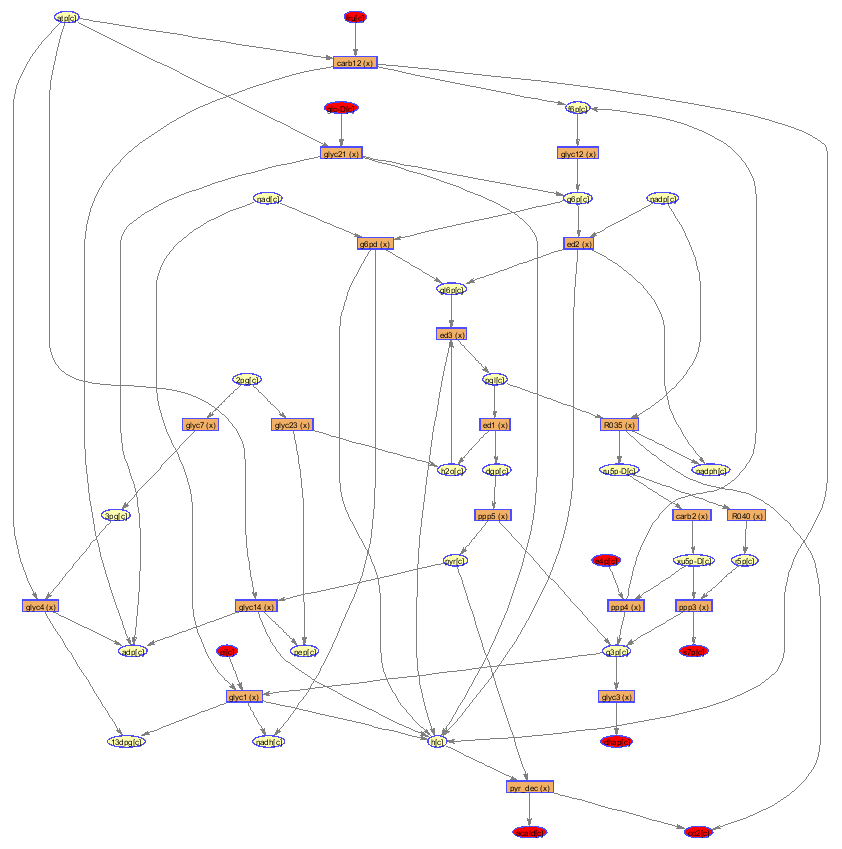	

**7. Perform FBA.**

The FBA results will be stored in the MATLAB workspace as variable *FBAsolution*.

FBAsolution=optimizeCbModel(model)

FBAsolution = struct with fields:
           x: [75×1 double]
           f: 0
           y: [60×1 double]
           w: [75×1 double]
        stat: 1
    origStat: 5
      solver: 'glpk'
        time: 0.0090
           v: [75×1 double]


**8. Visualize the model with FBA data.**

The model must be loaded before (see step 1). The FBA must be performed before (see step 7). Besides the list of 78 involved metabolites and the list of three (not 4 like in the step 2 because of FBA data) dead-end metabolites  the hypergraph layout will be generated by Paint4Net using the Bioinformatics Toolbox. The reaction nodes will contain flux rates according to FBA data. Interconnecting nodes will be in corresponding colors according to flux rates for each reaction.

[Involved_mets, Dead_ends] = draw_by_rxn(model, model.rxns, 'true', 'struc', {''}, {''}, FBAsolution.x)

Start_time = '2017_7_5_15_49_16.39'

End_time = '2017_7_5_15_49_17.376'

Total_time = '0_0_0_0_0_0.986'

Involved_mets = 60×1 cell array
    'f6p[c]'
    'g6p[c]'
    'atp[c]'
    'glc-D[c]'
    'adp[c]'
    'h[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nad[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'dgp[c]'
    'co2[c]'
    'ru5p-D[c]'
    'xu5p-D[c]'
    'e4p[c]'
    'g3p[c]'
    'r5p[c]'
    's7p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    '2pg[c]'
    'pep[c]'
    'acald[c]'
    'coa[c]'
    'accoa[c]'
    'etoh[c]'
    'ac[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'o2[c]'
    'fum[c]'
    'succ[c]'
    'oaa[c]'
    'cit[c]'
    'cis-aconitate[c]'
    'icit-D[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc3p[c]'
    'glyc-R[c]'
    'glyc[c]'
    'dha[c]'
    'xyl-D[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    'glcn[c]'
    '2dhglcn[c]'
    'sbt-D[c]'


Dead_ends = 2×1 cell array
    'o2[c]'
    'xyl-D[c]'


	

**9. Visualize the reactions of interest with FBA data.**

The model must be loaded before (see step 1). The list of reactions of interest must be created before (see step 3). The FBA must be performed before (see step 7). Besides the list of involved metabolites and the list of dead-end metabolites the hypergraph layout will be generated by Paint4Net using the Bioinformatics Toolbox. The reaction nodes will contain flux rates according to FBA data. Interconnecting nodes will be in corresponding colors according to flux rates for each reaction.

[Involved_mets, Dead_ends] = draw_by_rxn(model, rxns, 'true', 'struc', {''}, {''}, FBAsolution.x)

Start_time = '2017_7_5_15_49_17.41'

End_time = '2017_7_5_15_49_18.121'

Total_time = '0_0_0_0_0_0.711'

Involved_mets = 30×1 cell array
    'f6p[c]'
    'g6p[c]'
    'atp[c]'
    'glc-D[c]'
    'adp[c]'
    'h[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nad[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'dgp[c]'
    'co2[c]'
    'ru5p-D[c]'
    'xu5p-D[c]'
    'e4p[c]'
    'g3p[c]'
    'r5p[c]'
    's7p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    '2pg[c]'
    'pep[c]'
    'acald[c]'


Dead_ends = 8×1 cell array
    'glc-D[c]'
    'fru[c]'
    'co2[c]'
    'e4p[c]'
    's7p[c]'
    'dhap[c]'
    'pi[c]'
    'acald[c]'


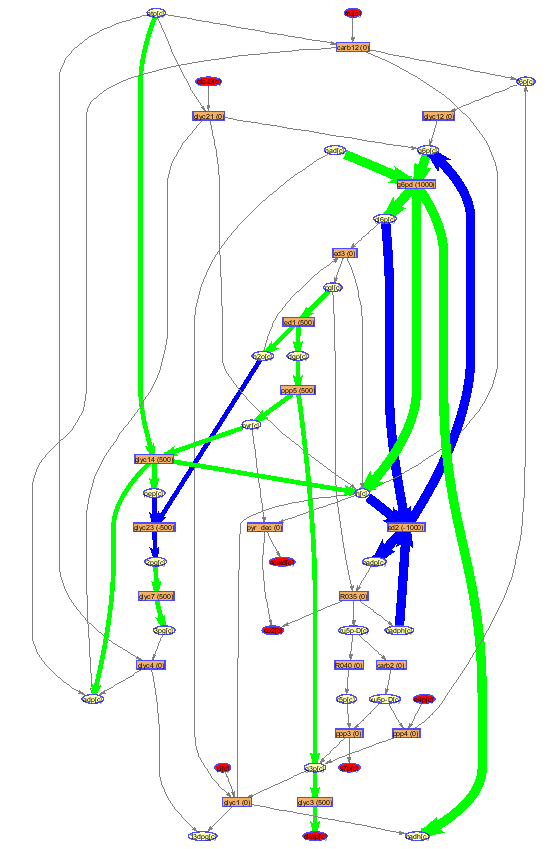

**10. Create a list of the excludable metabolites.**

The list with *atp*, *nad*, *adp*and *h* as excludable metabolites will be created in the MATLAB workspace as variable *excludeMets*.

excludeMets = {'atp[c]', 'nad[c]', 'adp[c]', 'h[c]'}

excludeMets = 1×4 cell array
    'atp[c]'    'nad[c]'    'adp[c]'    'h[c]'


**11. Visualize the model with excluded metabolites without FBA data.**

The model must be loaded before (see step 1). The list of excludable metabolites must be created before (see step 10). The first six arguments are used for the function [involvedMets, deadEnds] = draw_by_rxn(model, rxns, drawMap, direction, initialMet, excludeMets, flux), the last will take default value. Besides the list of involved metabolites and the list of dead-end metabolites the hypergraph layout will be generated by Paint4Net using the Bioinformatics Toolbox. The reaction nodes will contain”*x” *for flux rates. The generated layout will not contain any of metabolites declared in the list of excludable metabolites *excludeMets*. All interconnecting edges will be in gray because of no FBA data.

[Involved_mets, Dead_ends] = draw_by_rxn(model, model.rxns, 'true', 'struc', {''}, excludeMets)

Start_time = '2017_7_5_15_49_18.178'

End_time = '2017_7_5_15_49_19.121'

Total_time = '0_0_0_0_0_0.943'

Involved_mets = 56×1 cell array
    'f6p[c]'
    'g6p[c]'
    'glc-D[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'dgp[c]'
    'co2[c]'
    'ru5p-D[c]'
    'xu5p-D[c]'
    'e4p[c]'
    'g3p[c]'
    'r5p[c]'
    's7p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    '2pg[c]'
    'pep[c]'
    'acald[c]'
    'coa[c]'
    'accoa[c]'
    'etoh[c]'
    'ac[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'o2[c]'
    'fum[c]'
    'succ[c]'
    'oaa[c]'
    'cit[c]'
    'cis-aconitate[c]'
    'icit-D[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc3p[c]'
    'glyc-R[c]'
    'glyc[c]'
    'dha[c]'
    'xyl-D[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    'glcn[c]'
    '2dhglcn[c]'
    'sbt-D[c]'


Dead_ends = 3×1 cell array
    'glc-D[c]'
    'o2[c]'
    'xyl-D[c]'


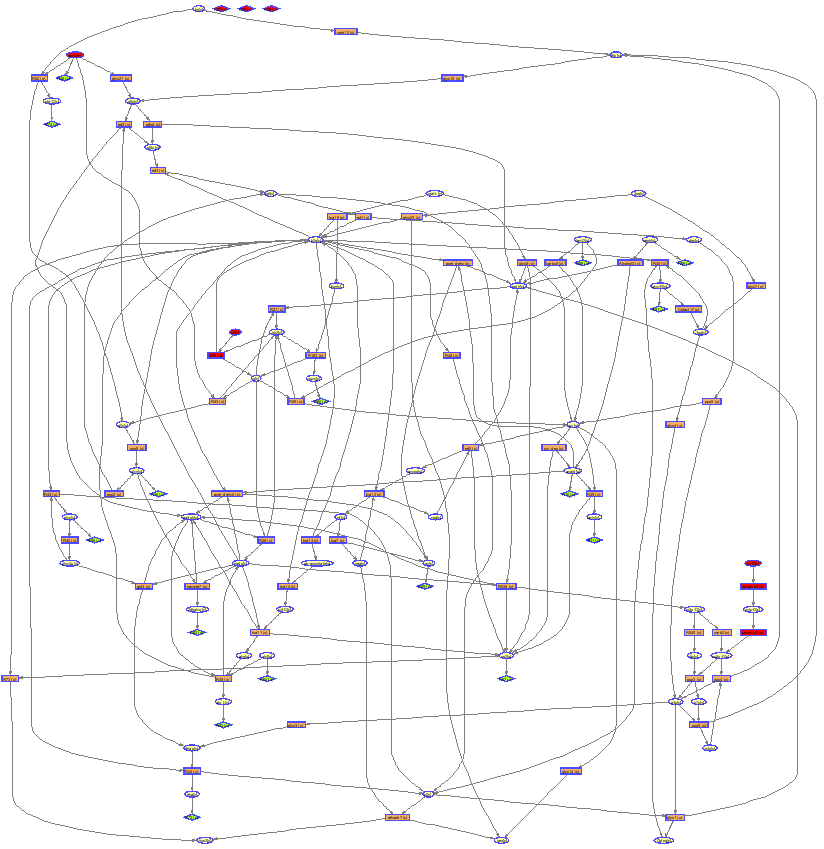

**12. Visualize the model with excluded metabolites with FBA data.**

The model must be loaded before (see step 1). The FBA must be performed before (see step 7). The list of excludable metabolites must be created before (see step 10). Besides the list of involved metabolites and the list of dead-end metabolites the hypergraph layout will be generated by Paint4Net using the Bioinformatics Toolbox. The reaction nodes will contain flux rates according to FBA data. Interconnecting nodes will be in corresponding colors according to flux rates for each reaction. The generated layout will not contain any of metabolites declared in the list of excludable metabolites *excludeMets*.

[Involved_mets, Dead_ends] = draw_by_rxn(model, model.rxns, 'true', 'struc', {''}, excludeMets, FBAsolution.x)

Start_time = '2017_7_5_15_49_19.145'

End_time = '2017_7_5_15_49_19.946'

Total_time = '0_0_0_0_0_0.801'

Involved_mets = 56×1 cell array
    'f6p[c]'
    'g6p[c]'
    'glc-D[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'dgp[c]'
    'co2[c]'
    'ru5p-D[c]'
    'xu5p-D[c]'
    'e4p[c]'
    'g3p[c]'
    'r5p[c]'
    's7p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    '2pg[c]'
    'pep[c]'
    'acald[c]'
    'coa[c]'
    'accoa[c]'
    'etoh[c]'
    'ac[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'o2[c]'
    'fum[c]'
    'succ[c]'
    'oaa[c]'
    'cit[c]'
    'cis-aconitate[c]'
    'icit-D[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc3p[c]'
    'glyc-R[c]'
    'glyc[c]'
    'dha[c]'
    'xyl-D[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    'glcn[c]'
    '2dhglcn[c]'
    'sbt-D[c]'


Dead_ends = 2×1 cell array
    'o2[c]'
    'xyl-D[c]'


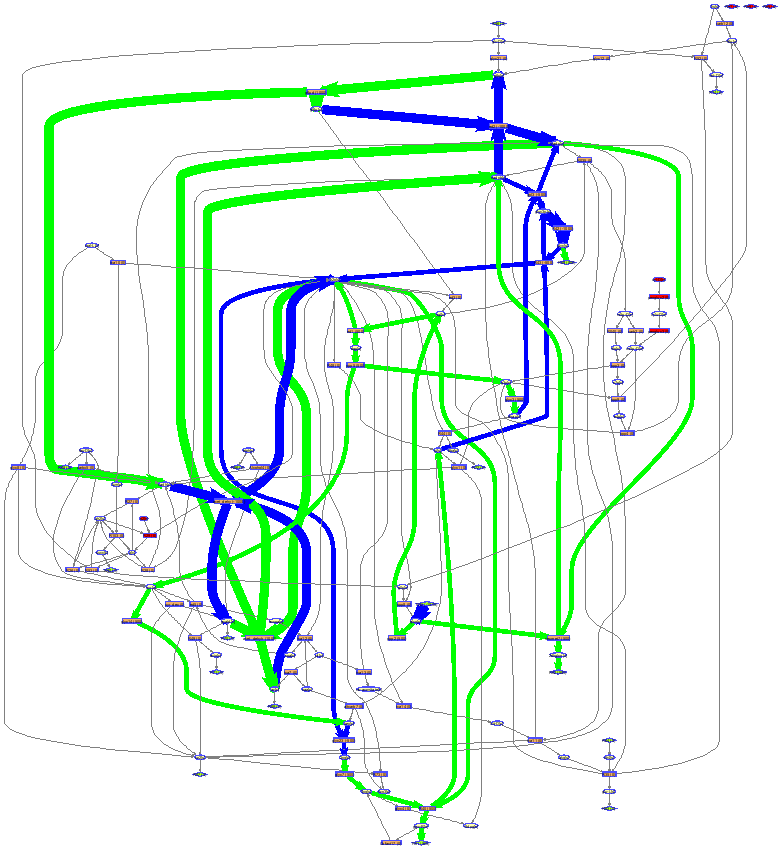

**13. Find involved reactions, involved metabolites and dead-end metabolite in the radius of 2 reactions from the metabolite of interest (in this case etoh[c]) without visualization, without FBA data.**

The model must be loaded before (see step 1). The first four arguments are used for the function [directionRxns, involvedMets, deadEnds]=draw_by_met(model, metAbbr, drawMap, radius, direction, excludeMets, flux), the rest will take default values. The expected involved reactions are: 'Alcohol4', 'R66', 'Cofact17', 'R27', 'R28', 'R35', 'R42', 'R48', 'R49', 'R70', 'R73', 'acet_dehy', 'acet_dehyh', 'carb12', 'carbx5', 'ed2', 'ed3', 'ed5', 'g6pd', 'glyc1', 'glyc14', 'glyc21', 'glyc8', 'gpl3', 'pengluc3', 'ppp2', 'ppp8', 'pyr_dec', 'secmet7' and 'tca12'. The list of involved reactions will be created in the MATLAB workspace as variable *directionRxns*. The expected involved metabolites are: 'f6p[c]', 'g6p[c]', 'atp[c]', 'glc-D[c]', 'adp[c]', 'h[c]', 'fru[c]', 'nadp[c]', 'gl6p[c]', 'nadph[c]', 'nad[c]', 'nadh[c]', 'h2o[c]', 'pgl[c]', 'co2[c]', 'xu5p-D[c]', 'g3p[c]', 'pyr[c]', 'dhap[c]', 'pi[c]', '13dpg[c]', '3pg[c]', 'pep[c]', 'acald[c]', 'coa[c]', 'accoa[c]', 'etoh[c]', 'ac[c]', 'lac-D[c]', 'q[c]', 'qh2[c]', 'oaa[c]', 'cit[c]', 'akg[c]', 'nh4[c]', 'glu-L[c]', 'mal-L[c]', 'hco3[c]', 'glyc3p[c]', 'glyc-R[c]', 'glyc[c]', 'xylu-D[c]', 'acin[c]', 'gllc[e]', 'glcn[e]', 'glcn[c]' and '2dhglcn[c]'. The list of involved metabolites will be created in the MATLAB workspace as variable *involvedMets*. The expected dead-end metabolites are: 'f6p[c]', 'glc-D[c]', 'fru[c]', 'xu5p-D[c]', 'g3p[c]', 'dhap[c]', '13dpg[c]', '3pg[c]', 'pep[c]', 'lac-D[c]', 'q[c]', 'qh2[c]', 'oaa[c]', 'cit[c]', 'akg[c]', 'nh4[c]', 'glu-L[c]', 'mal-L[c]', 'hco3[c]', 'glyc-R[c]', 'glyc[c]', 'xylu-D[c]', 'acin[c]', '2dhglcn[c]' and 'gllc[c]'. The list of dead-end metabolites will be created in the MATLAB workspace as variable *deadEnds*.

[directionRxns,involvedMets,deadEnds] = draw_by_met(model,{'etoh[c]'},'false',2)

Start_time = '2017_7_5_15_49_20.01'

End_time = '2017_7_5_15_49_20.888'

Total_time = '0_0_0_0_0_0.878'

directionRxns = 30×1 cell array
    'Alcohol4'
    'R66'
    'glyc21'
    'carb12'
    'ed2'
    'g6pd'
    'ed3'
    'glyc1'
    'glyc14'
    'pyr_dec'
    'ed5'
    'acet_dehy'
    'acet_dehyh'
    'carbx5'
    'R27'
    'R28'
    'tca12'
    'R35'
    'glyc8'
    'gpl3'
    'Cofact17'
    'R42'
    'pengluc3'
    'R48'
    'R49'
    'ppp8'
    'secmet7'
    'ppp2'
    'R70'
    'R73'


involvedMets = 46×1 cell array
    'f6p[c]'
    'g6p[c]'
    'atp[c]'
    'glc-D[c]'
    'adp[c]'
    'h[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nad[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'co2[c]'
    'xu5p-D[c]'
    'g3p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    'pep[c]'
    'acald[c]'
    'coa[c]'
    'accoa[c]'
    'etoh[c]'
    'ac[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'oaa[c]'
    'cit[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc3p[c]'
    'glyc-R[c]'
    'glyc[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    'glcn[c]'
    '2dhglcn[c]'


deadEnds = 25×1 cell array
    'f6p[c]'
    'glc-D[c]'
    'fru[c]'
    'xu5p-D[c]'
    'g3p[c]'
    'dhap[c]'
    '13dpg[c]'
    '3pg[c]'
    'pep[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'oaa[c]'
    'cit[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc-R[c]'
    'glyc[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    '2dhglcn[c]'


**14. Visualize the part of the model in the** **radius of 2 reactions from the metabolite of interest (in this case etoh[c]) without FBA data.**

The model must be loaded before (see step 1). The first four arguments are used for the function [directionRxns, involvedMets, deadEnds] = draw_by_met(model, metAbbr, drawMap, radius, direction, excludeMets, flux), the rest will take default values. Besides the list of involved reactions, the list of involved metabolites and the list of dead-end metabolites the hypergraph layout will be generated by Paint4Net using the Bioinformatics Toolbox. The reaction nodes will contain *x *for flux rates. All interconnecting edges will be in gray because of no FBA data.

[directionRxns, involvedMets, deadEnds] = draw_by_met(model, {'etoh[c]'}, 'true', 2)

Start_time = '2017_7_5_15_49_20.965'

End_time = '2017_7_5_15_49_21.62'

Total_time = '0_0_0_0_0_0.655'

directionRxns = 30×1 cell array
    'Alcohol4'
    'R66'
    'glyc21'
    'carb12'
    'ed2'
    'g6pd'
    'ed3'
    'glyc1'
    'glyc14'
    'pyr_dec'
    'ed5'
    'acet_dehy'
    'acet_dehyh'
    'carbx5'
    'R27'
    'R28'
    'tca12'
    'R35'
    'glyc8'
    'gpl3'
    'Cofact17'
    'R42'
    'pengluc3'
    'R48'
    'R49'
    'ppp8'
    'secmet7'
    'ppp2'
    'R70'
    'R73'


involvedMets = 46×1 cell array
    'f6p[c]'
    'g6p[c]'
    'atp[c]'
    'glc-D[c]'
    'adp[c]'
    'h[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nad[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'co2[c]'
    'xu5p-D[c]'
    'g3p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    'pep[c]'
    'acald[c]'
    'coa[c]'
    'accoa[c]'
    'etoh[c]'
    'ac[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'oaa[c]'
    'cit[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc3p[c]'
    'glyc-R[c]'
    'glyc[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    'glcn[c]'
    '2dhglcn[c]'


deadEnds = 25×1 cell array
    'f6p[c]'
    'glc-D[c]'
    'fru[c]'
    'xu5p-D[c]'
    'g3p[c]'
    'dhap[c]'
    '13dpg[c]'
    '3pg[c]'
    'pep[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'oaa[c]'
    'cit[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc-R[c]'
    'glyc[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    '2dhglcn[c]'


**15. Visualize the part of the model in the** **radius of 2 reactions from the metabolite of interest (in this case etoh[c]) with FBA data.**

The model must be loaded before (see step 1). The FBA must be performed before (see step 7). Besides the list of involved reactions, the list of involved metabolites and the list of dead-end metabolites the hypergraph layout will be generated by Paint4Net using the Bioinformatics Toolbox. The reaction nodes will contain flux rates according to FBA data. Interconnecting nodes will be in corresponding colors according to flux rates for each reaction.

[directionRxns, involvedMets, deadEnds] = draw_by_met(model, {'etoh[c]'}, 'true', 2, 'struc', {''}, FBAsolution.x)

Start_time = '2017_7_5_15_49_21.663'

End_time = '2017_7_5_15_49_22.163'

Total_time = '0_0_0_0_0_0.5'

directionRxns = 30×1 cell array
    'Alcohol4'
    'R66'
    'glyc21'
    'carb12'
    'ed2'
    'g6pd'
    'ed3'
    'glyc1'
    'glyc14'
    'pyr_dec'
    'ed5'
    'acet_dehy'
    'acet_dehyh'
    'carbx5'
    'R27'
    'R28'
    'tca12'
    'R35'
    'glyc8'
    'gpl3'
    'Cofact17'
    'R42'
    'pengluc3'
    'R48'
    'R49'
    'ppp8'
    'secmet7'
    'ppp2'
    'R70'
    'R73'


involvedMets = 46×1 cell array
    'f6p[c]'
    'g6p[c]'
    'atp[c]'
    'glc-D[c]'
    'adp[c]'
    'h[c]'
    'fru[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nad[c]'
    'nadh[c]'
    'h2o[c]'
    'pgl[c]'
    'co2[c]'
    'xu5p-D[c]'
    'g3p[c]'
    'pyr[c]'
    'dhap[c]'
    'pi[c]'
    '13dpg[c]'
    '3pg[c]'
    'pep[c]'
    'acald[c]'
    'coa[c]'
    'accoa[c]'
    'etoh[c]'
    'ac[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'oaa[c]'
    'cit[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc3p[c]'
    'glyc-R[c]'
    'glyc[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    'glcn[c]'
    '2dhglcn[c]'


deadEnds = 25×1 cell array
    'f6p[c]'
    'glc-D[c]'
    'fru[c]'
    'xu5p-D[c]'
    'g3p[c]'
    'dhap[c]'
    '13dpg[c]'
    '3pg[c]'
    'pep[c]'
    'lac-D[c]'
    'q[c]'
    'qh2[c]'
    'oaa[c]'
    'cit[c]'
    'akg[c]'
    'nh4[c]'
    'glu-L[c]'
    'mal-L[c]'
    'hco3[c]'
    'glyc-R[c]'
    'glyc[c]'
    'xylu-D[c]'
    'acin[c]'
    'gllc[c]'
    '2dhglcn[c]'


**16. Visualize substrates in the radius of 2 reactions from the metabolite of interest (in this case etoh[c]) with FBA data.**

The model must be loaded before (see step 1). The FBA must be performed before (see step 7). Besides the list of involved reactions, the list of involved metabolites and the list of dead-end metabolites the hypergraph layout will be generated by Paint4Net using the Bioinformatics Toolbox where only substrates for g6p[c] in the radius of 2 reactions will be visualized. The reaction nodes will contain flux rates according to FBA data. Interconnecting nodes will be in corresponding colors according to flux rates for each reaction.

[directionRxns, involvedMets, deadEnds] = draw_by_met(model, {'g6p[c]'}, 'true', 2, 'sub', {''}, FBAsolution.x)

Start_time = '2017_7_5_15_49_22.198'

End_time = '2017_7_5_15_49_22.544'

Total_time = '0_0_0_0_0_0.346'

directionRxns = 6×1 cell array
    'ed2'
    'g6pd'
    'glyc14'
    'acet_dehyh'
    'secmet7'
    'ppp2'


involvedMets = 11×1 cell array
    'g6p[c]'
    'atp[c]'
    'h[c]'
    'nadp[c]'
    'gl6p[c]'
    'nadph[c]'
    'nad[c]'
    'h2o[c]'
    'pyr[c]'
    'acald[c]'
    'glcn[c]'


deadEnds = 4×1 cell array
    'nad[c]'
    'h2o[c]'
    'pyr[c]'
    'acald[c]'


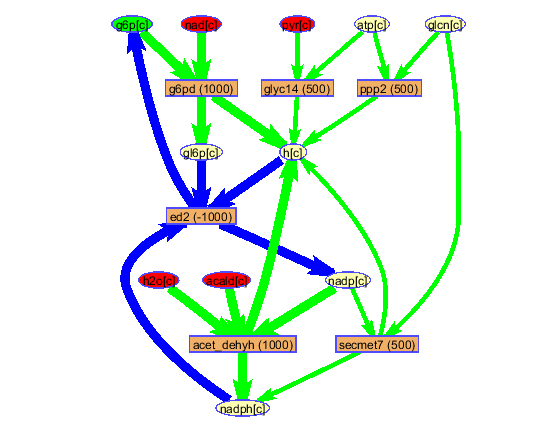

**17. Visualize products in the radius of 2 reactions from the metabolite of interest (in this case atp[c]) with FBA data.**

The model must be loaded before (see step 1). The FBA must be performed before (see step 7). Besides the list of involved reactions, the list of involved metabolites and the list of dead-end metabolites the hypergraph layout will be generated by Paint4Net using the Bioinformatics Toolbox where only products of atp[c] in the radius of 2 reactions will be visualized. The reaction nodes will contain flux rates according to FBA data. Interconnecting nodes will be in corresponding colors according to flux rates for each reaction.

[directionRxns, involvedMets, deadEnds] = draw_by_met(model, {'atp[c]'}, 'true', 2, 'prod', {''}, FBAsolution.x)

Start_time = '2017_7_5_15_49_22.579'

End_time = '2017_7_5_15_49_22.939'

Total_time = '0_0_0_0_0_0.36'

directionRxns = 8×1 cell array
    'glyc14'
    'ppp2'
    'ed2'
    'ed1'
    'glyc23'
    'acet_dehy'
    'gpl3'
    'R42'


involvedMets = 14×1 cell array
    'g6p[c]'
    'atp[c]'
    'adp[c]'
    'h[c]'
    'nadp[c]'
    'nad[c]'
    'h2o[c]'
    'pgl[c]'
    'dgp[c]'
    '2pg[c]'
    'pep[c]'
    'acald[c]'
    'glyc3p[c]'
    'glyc[c]'


deadEnds = 6×1 cell array
    'g6p[c]'
    'nad[c]'
    'dgp[c]'
    '2pg[c]'
    'acald[c]'
    'glyc[c]'


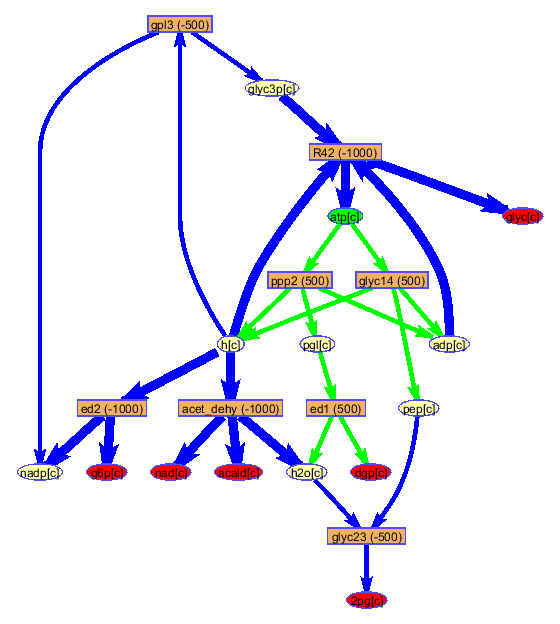

## Acknowledgments

Authors are thankful to Ines Thiele who inspired to make a simple visualization software for COBRA models. 

This work is funded by a project of European Structural Fund Nr. 2009/0207/1DP/1.1.1.2.0/09/APIA/VIAA/128 “Latvian Interdisciplinary Interuniversity Scientific Group of Systems Biology” www.sysbio.lv.

## REFERENCES

Aurich, M.K., Thiele, I., 2012. Contextualization Procedure and Modeling of Monocyte Specific TLR Signaling. PLoS One 7, e49978. doi:10.1371/journal.pone.0049978

Contador, C.A., Rodr?guez, V., Andrews, B.A., Asenjo, J.A., 2015. Genome-scale reconstruction of Salinispora tropica CNB-440 metabolism to study strain-specific adaptation. Antonie Van Leeuwenhoek 108, 1075–1090. doi:10.1007/s10482-015-0561-9

Demidenko, A., Akberdin, I.R., Allemann, M., Allen, E.E., Kalyuzhnaya, M.G., 2017. Fatty Acid Biosynthesis Pathways in Methylomicrobium buryatense 5G(B1). Front. Microbiol. 7. doi:10.3389/fmicb.2016.02167

Koussa, J., Chaiboonchoe, A., Salehi-Ashtiani, K., 2014. Computational Approaches for Microalgal Biofuel Optimization: A Review. Biomed Res. Int. 2014, 1–12. doi:10.1155/2014/649453

Mao, L., Verwoerd, W.S., 2014. ORCA: a COBRA toolbox extension for model-driven discovery and analysis. Bioinformatics 30, 584–585. doi:10.1093/bioinformatics/btt723

Meitalovs, J., Stalidzans, E., 2013. Analysis of synthetic metabolic pathways solution space, in: 2013 International Conference on System Science and Engineering (ICSSE). Ieee, pp. 183–187. doi:10.1109/ICSSE.2013.6614656

Palsson, B.O., 2006. Systems Biology: Properties of Reconstructed Networks. Cambridge University Press, New York.

Pentjuss, A., Odzina, I., Kostromins, A., Fell, D.A., Stalidzans, E., Kalnenieks, U., 2013. Biotechnological potential of respiring Zymomonas mobilis: a stoichiometric analysis of its central metabolism. J. Biotechnol. 165, 1–10. doi:10.1016/j.jbiotec.2013.02.014

Pentjuss, A., Stalidzans, E., Liepins, J., Kokina, A., Martynova, J., Zikmanis, P., Mozga, I., Scherbaka, R., Hartman, H., Poolman, M.G., Fell, D.A., Vigants, A., 2017. Model-based biotechnological potential analysis of Kluyveromyces marxianus central metabolism. J. Ind. Microbiol. Biotechnol. doi:10.1007/s10295-017-1946-8

Richards, M.A., Lie, T.J., Zhang, J., Ragsdale, S.W., Leigh, J.A., Price, N.D., 2016. Exploring Hydrogenotrophic Methanogenesis: a Genome Scale Metabolic Reconstruction of Methanococcus maripaludis. J. Bacteriol. 198, 3379–3390. doi:10.1128/JB.00571-16

Rove, Z., Mednis, M., Odzina, I., 2012. Biochemical networks comparison tool, in: 5th International Scientific Conference on Applied Information and Communication Technologies. Jelgava, Latvia., pp. 306–311.

Rubina, T., Stalidzans, E., 2013. BINESA — A software tool for evolution modelling of biochemical networks’ structure, in: 2013 IEEE 14th International Symposium on Computational Intelligence and Informatics (CINTI). IEEE, pp. 345–350. doi:10.1109/CINTI.2013.6705218

Thiele, I., Palsson, B.Ø., 2010. A protocol for generating a high-quality genome-scale metabolic reconstruction. Nat. Protoc. 5, 93–121. doi:10.1038/nprot.2009.203